# Test DecisionTreeClass

Initialise

## Todo: 

- check nan values in quick test, 

- update all loops (nbayes, random forest and dtree) to use appendResult as the random seed increment

- see if max depth can be used somehow

- use a smaller subset of max splits

clear
clc
clf
close all
load letterDatasetClass.mat

### Quick Test

treeQuickTest = performQuickTreeAnalysis(letterDatasetNotNormalised, "treeQuickTest.csv");

Starting decision tree analysis...
Completed decision tree analysis


% load results from csv file:
treeQuickTestResults = LetterDecisionTreeResults.getInstanceFromCsvResults("treeQuickTest.csv");
% display results table
disp(treeQuickTestResults.resultsTable);

    numberOfFolds    minLeafSize    minParentSize    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    predictTime    randomSeed
    _____________    ___________    _____________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ___________    __________

          2               1          

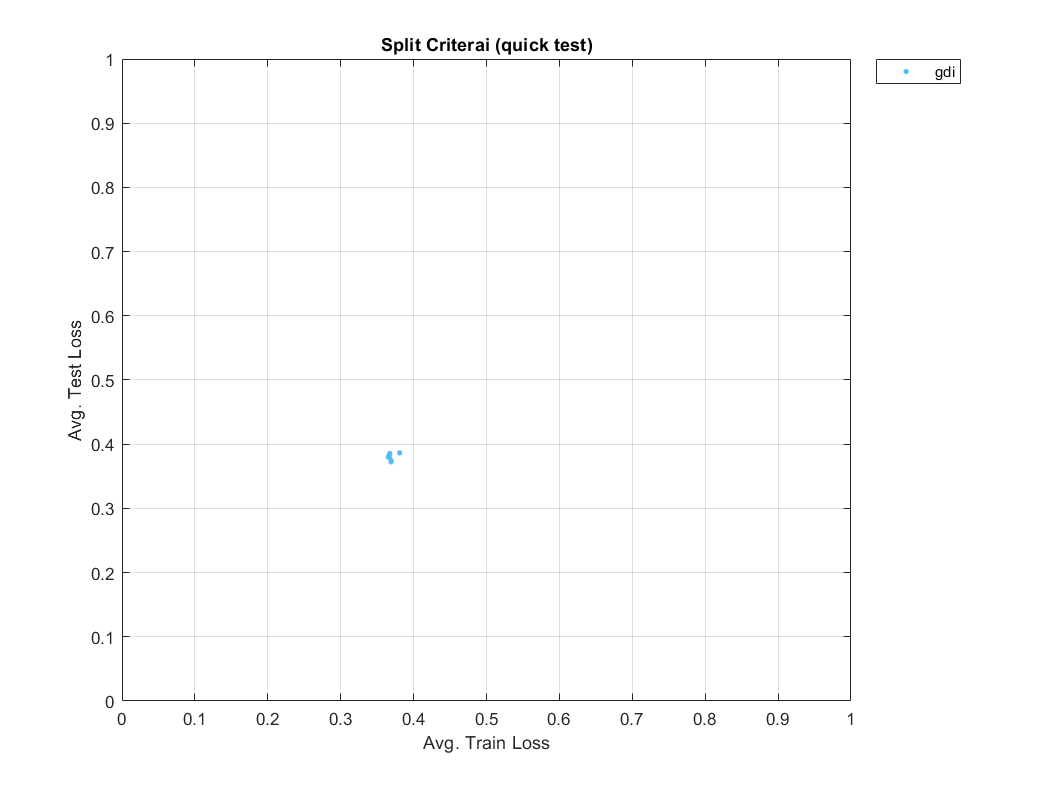

% plot split criteria comparison
treeQuickTestResults.plotCriteriaLoss("Split Criterai (quick test)")

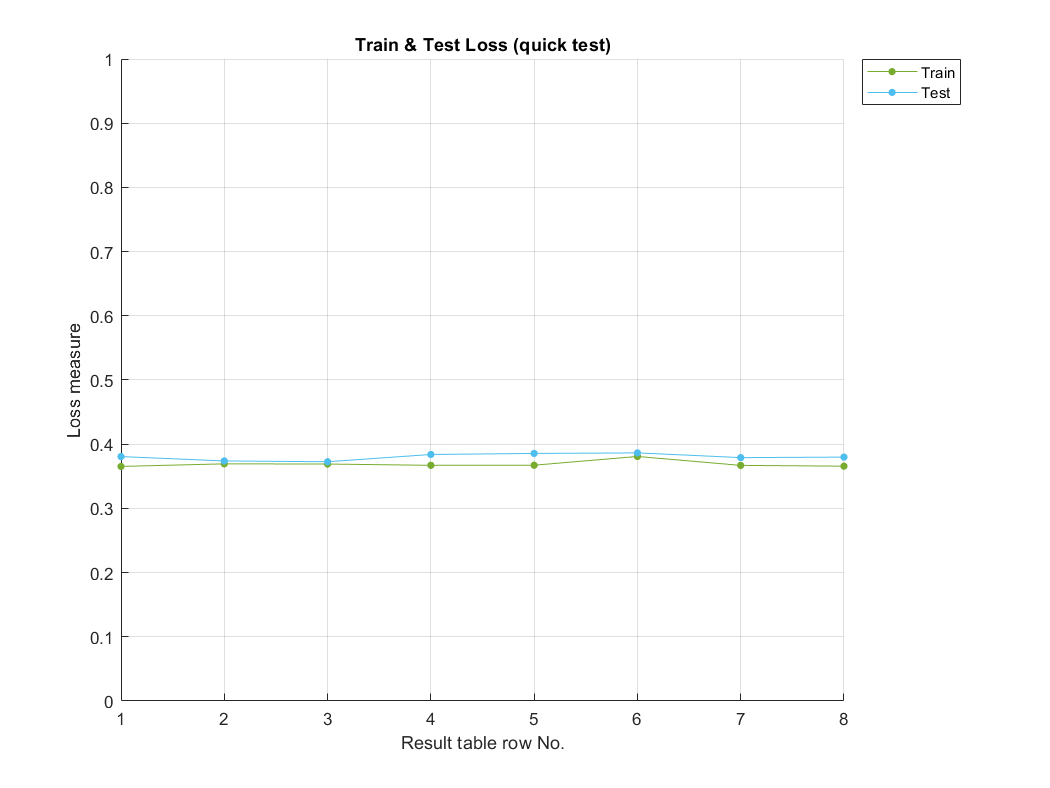

PlotUtil.plotLossTestTrainComparison(treeQuickTestResults.resultsTable,...
 "Train & Test Loss (quick test)");

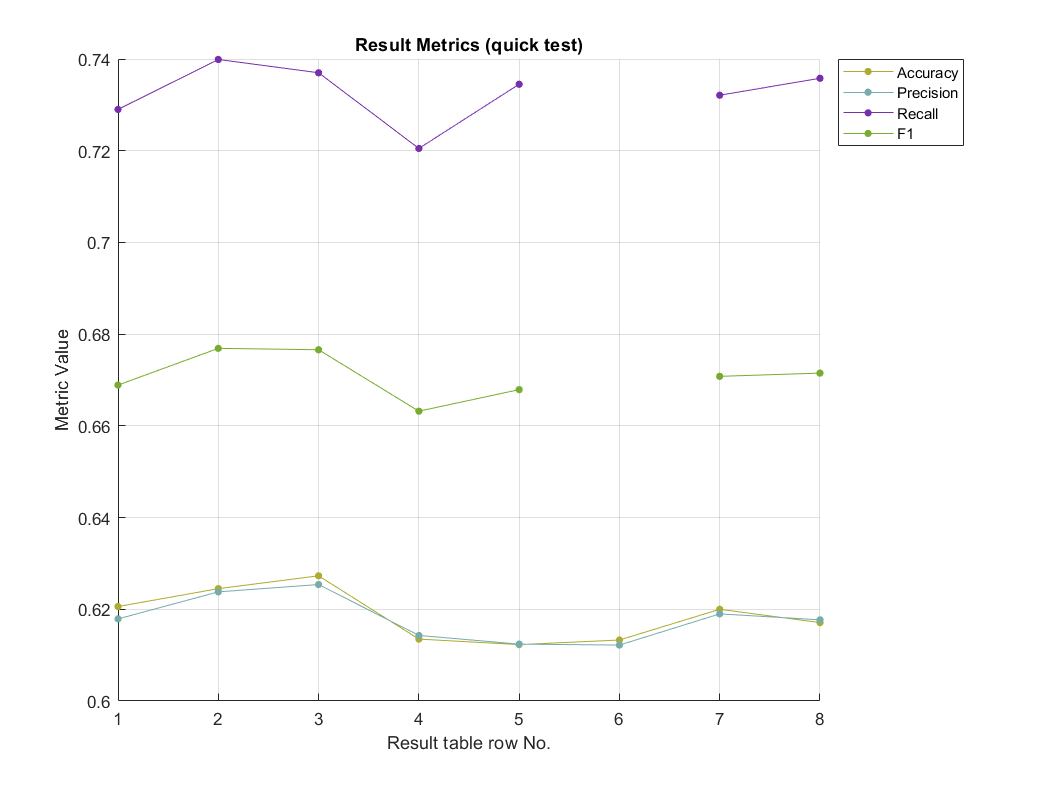

% plot metrics
PlotUtil.plotMetrics(treeQuickTestResults.resultsTable, "Result Metrics (quick test)");

## Run analysis on all columns, all parameters:

**letterDatasetNotNormalised** and **letterDatasetStandardised** are used in this section.

### Perform analysis on unnormalised dataset (takes time)

treeAllFeatureResultsNotNormalised = performTreeAnalysis(letterDatasetNotNormalised, "treeAllFeatureResultsNotNormalised.csv");

Starting decision tree analysis...
Completed decision tree analysis


### Perform analysis on normalised dataset (takes time)

treeAllFeatureResultsNormalised = performTreeAnalysis(letterDatasetStandardised, "treeAllFeatureResultsNormalised.csv");

Starting decision tree analysis...
Completed decision tree analysis


### Display the results of test and train Loss on normalised and unnormalised

datasets: From this we can see that normalisation has no effect

#### Results of the dataset that has not been normalised

% load results from csv file:
treeAllFeatureResultsNotNormalised = LetterDecisionTreeResults.getInstanceFromCsvResults("treeAllFeatureResultsNotNormalised.csv");
% display results table
disp(treeAllFeatureResultsNotNormalised.resultsTable);

    numberOfHoldOutRun    trainValidateProportion    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    __________________    _______________________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________

             1                      0.8                   25         {'gdi'     }        0.6304         0.6244         0.3861          0.3737           NaN         NaN       3199         0.7031   


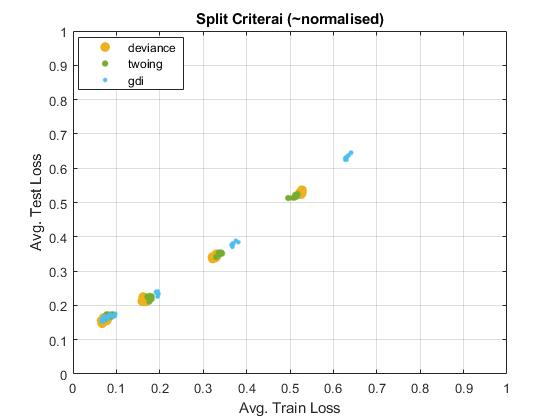

% plot split criteria comparison
treeAllFeatureResultsNotNormalised.plotCriteriaLoss("Split Criteria (~normalised)")

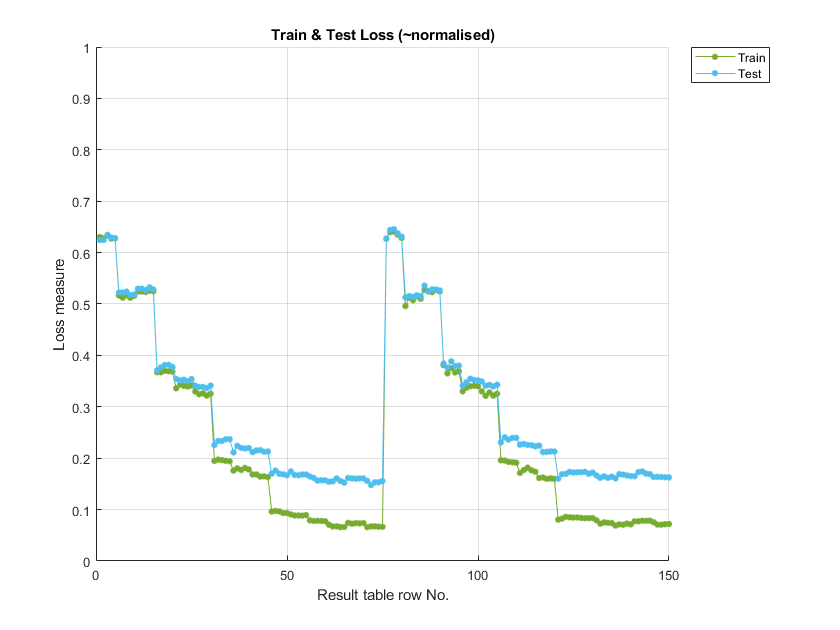

% plot test train comparison
PlotUtil.plotLossTestTrainComparison(treeAllFeatureResultsNotNormalised.resultsTable,...
 "Train & Test Loss (~normalised)");

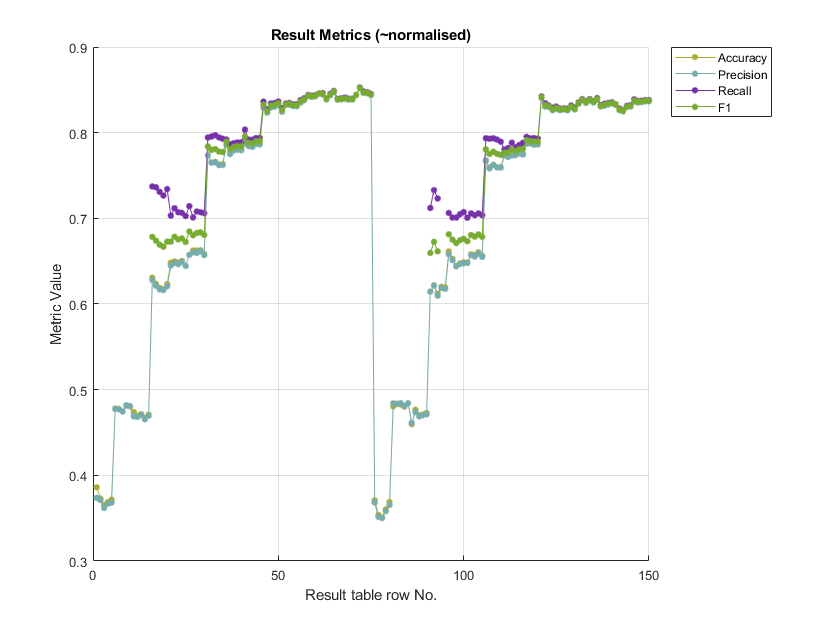

% plot metrics
PlotUtil.plotMetrics(treeAllFeatureResultsNotNormalised.resultsTable, "Result Metrics (~normalised)");

#### Normalised dataset results

% load results table from csv
treeAllFeatureResultsNormalised = LetterDecisionTreeResults.getInstanceFromCsvResults("treeAllFeatureResultsNormalised.csv");
% display results table
disp(treeAllFeatureResultsNormalised.resultsTable);

    numberOfHoldOutRun    trainValidateProportion    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    __________________    _______________________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________

             1                      0.8                   25         {'gdi'     }        0.6304         0.6244         0.3861          0.3737           NaN         NaN       3199         0.4063   


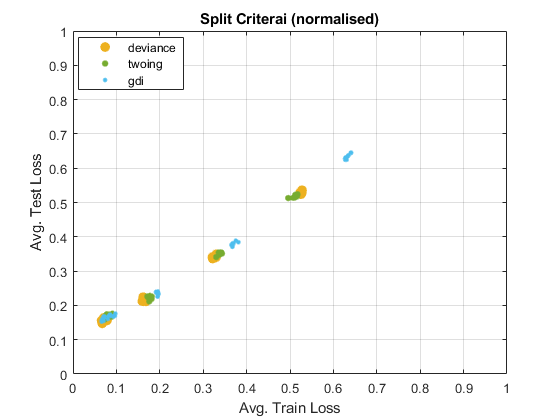

% plot split criteria comparison
treeAllFeatureResultsNormalised.plotCriteriaLoss("Split Criterai (normalised)");

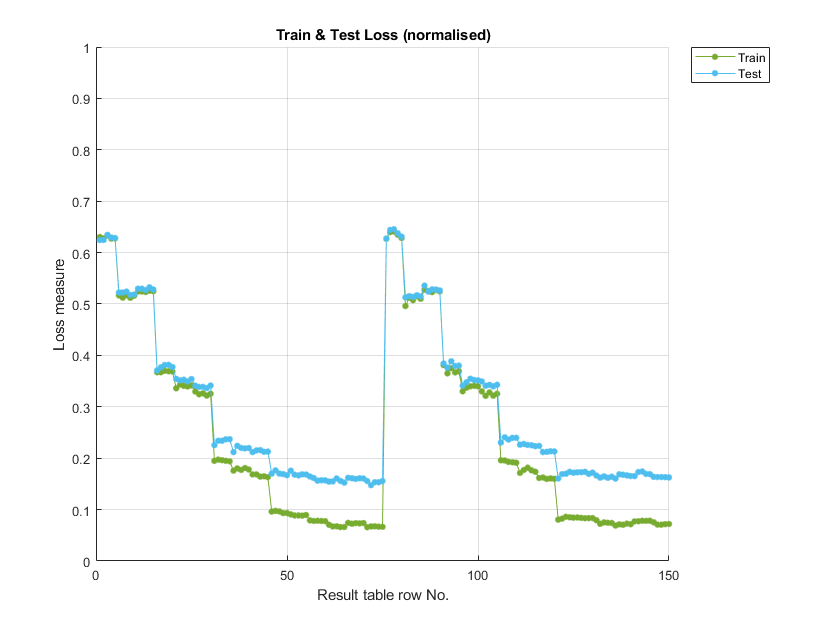

% plot train / test loss comparison
PlotUtil.plotLossTestTrainComparison(treeAllFeatureResultsNormalised.resultsTable,...
 "Train & Test Loss (normalised)");

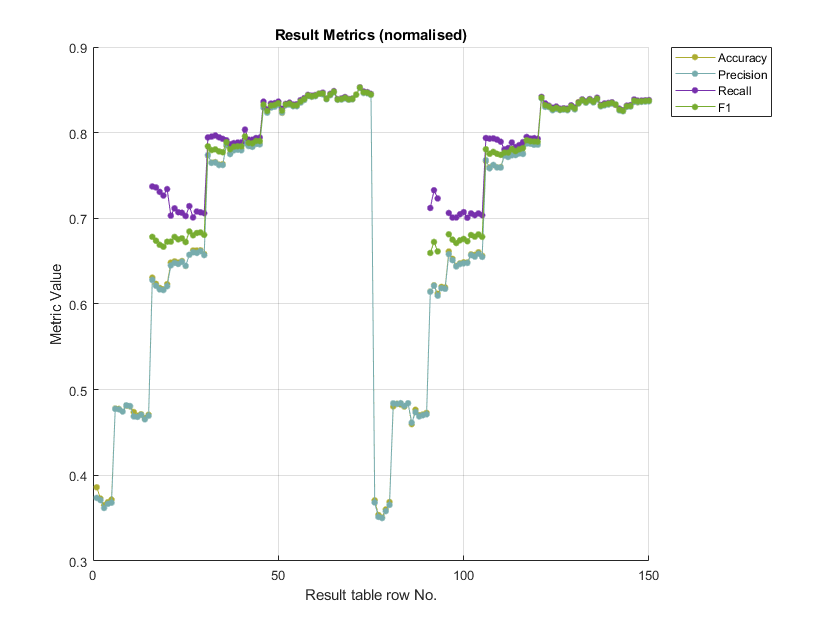

% plot metrics
PlotUtil.plotMetrics(treeAllFeatureResultsNormalised.resultsTable, "Result Metrics (normalised)");

## Feature selection removing features

Run the same hyperparameters as in the previous test, this time removing features identified as good candidates for removal during the dataset analysis

The following features have been removed in the dataset:

- xBox

- yBox

- width

- height

clear
clc
clf
close all
load letterDatasetClass.mat;

## Perform analysis on normalised dataset (takes time)

letterDatasetStandardisedReducedFeatures is the one that is used

treeAllFeatureResultsNormalised = performTreeAnalysis(letterDatasetStandardisedReducedFeatures, "selectedFeatureResultsNormalised.csv");

Starting decision tree analysis...
Completed decision tree analysis


### Analysis on the dataset with features removed, and normalised

% load results table from csv
treeAllFeatureResultsNormalised = LetterDecisionTreeResults.getInstanceFromCsvResults("selectedFeatureResultsNormalised.csv");
% display results table
disp(treeAllFeatureResultsNormalised.resultsTable);

    numberOfHoldOutRun    trainValidateProportion    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    __________________    _______________________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________

             1                      0.8                   25         {'gdi'     }        0.6304         0.6244         0.3861          0.3737           NaN         NaN       3199         1.6094   


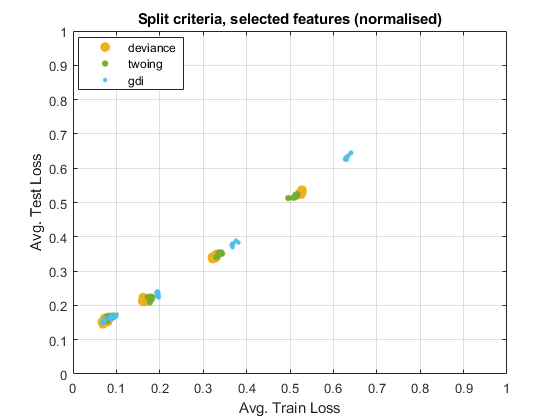

% plot split criteria comparison
treeAllFeatureResultsNormalised.plotCriteriaLoss("Split criteria, selected features (normalised)");

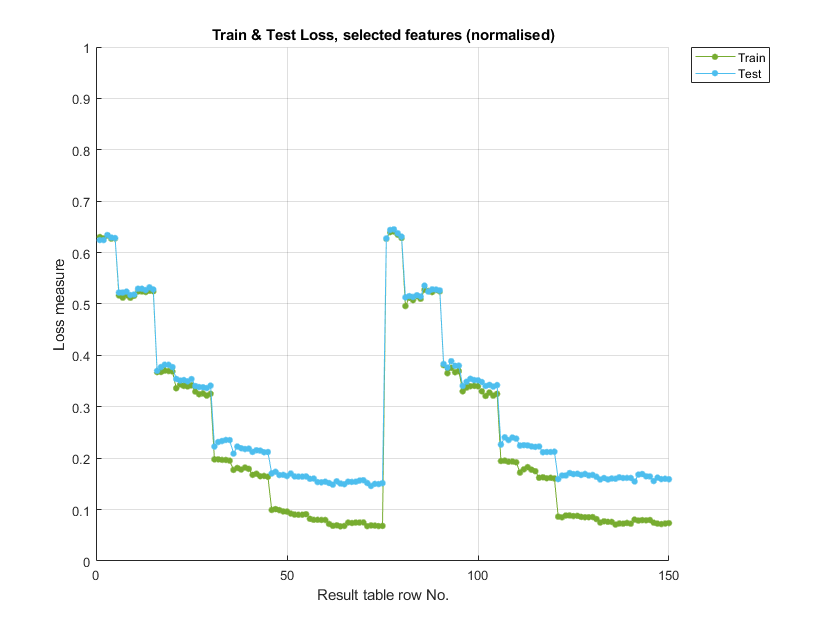

% plot train / test loss comparison
PlotUtil.plotLossTestTrainComparison(treeAllFeatureResultsNormalised.resultsTable,...
 "Train & Test Loss, selected features (normalised)");

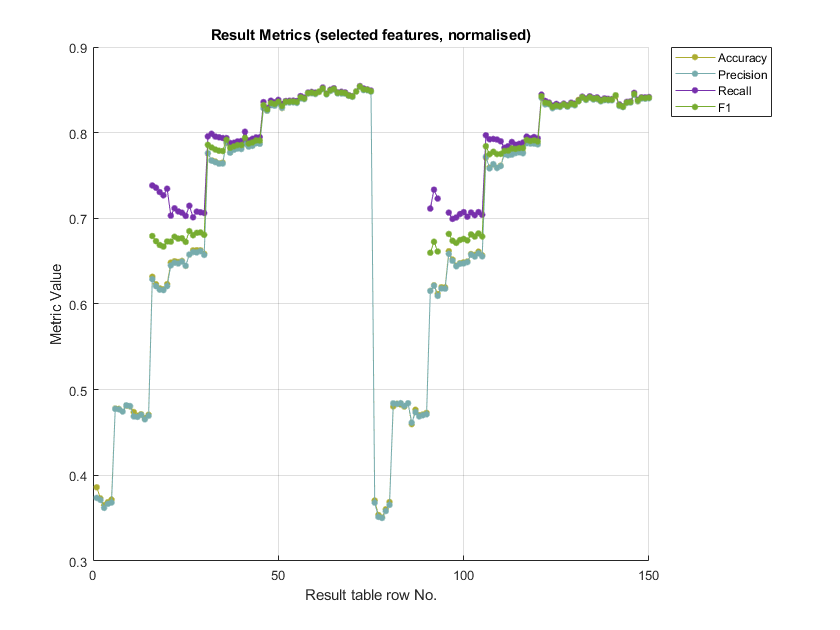

% plot metrics
PlotUtil.plotMetrics(treeAllFeatureResultsNormalised.resultsTable, "Result Metrics (selected features, normalised)");

## TODO Remove this: Plot results: deviance split criterion looks more accurate, the time

taken is not greatly reduced,the Losses are slightly increased when comparing the plot to the plot with all the features.

  LetterDecisionTreeResults with properties:

             resultsTable: [150×12 table]
       resultsColumnNames: [1×12 string]
    outputResultsFilename: "selectedFeatureResultsselectedFeatureResults.csv"
               fileHandle: -1



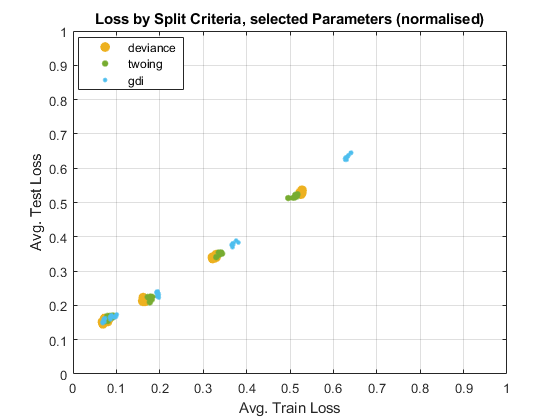

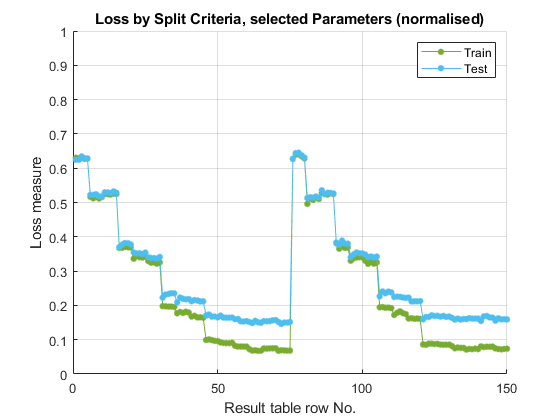

    numberOfHoldOutRun    trainValidateProportion    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    __________________    _______________________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________

             1                      0.8                   25         {'gdi'     }        0.6304         0.6244         0.3861          0.3737           NaN         NaN       3199         0.3438   


displayFeatureResults(treeAllFeatureResultsNormalised, "Loss by Split Criteria, selected Parameters (normalised)" );

## Perform analysiss on deviance split criterion, as this criterion is consistently the most accurate.

load letterDatasetClass.mat;
devianceHyperparameters = DTreeHyperparametersClass.getDevianceSplitCriteriaInstance();
treeAllFeatureClass = LetterDecisionTreeClass(letterDatasetStandardised);
% display info during run?
treeAllFeatureClass.debug = false;
treeDevianceSplitResults = treeAllFeatureClass.performDTreeHyperameterAnalysis(devianceHyperparameters, "treeSelectDevianceSplitResults.csv");

Starting decision tree analysis...


ans = 5×1 categorical array
     F 
     X 
     C 
     E 
     O 


Misclassified 1361 entries out of 3199. 42.5445 pct
Training loss: 0.42. Test Loss: 0.42


ans = 5×1 categorical array
     C 
     I 
     B 
     D 
     B 


Misclassified 1381 entries out of 3199. 43.1697 pct
Training loss: 0.41. Test Loss: 0.42


ans = 5×1 categorical array
     R 
     N 
     P 
     D 
     B 


Misclassified 1329 entries out of 3199. 41.5442 pct
Training loss: 0.42. Test Loss: 0.42


ans = 5×1 categorical array
     F 
     G 
     Z 
     T 
     O 


Misclassified 1312 entries out of 3199. 41.0128 pct
Training loss: 0.41. Test Loss: 0.41


ans = 5×1 categorical array
     O 
     A 
     C 
     M 
     B 


Misclassified 1315 entries out of 3199. 41.1066 pct
Training loss: 0.40. Test Loss: 0.41


ans = 5×1 categorical array
     N 
     T 
     L 
     O 
     X 


Misclassified 1374 entries out of 3199. 42.9509 pct
Training loss: 0.42. Test Loss: 0.43


ans = 5×1 categorical array
     X 
     A 
     F 
     X 
     O 


Misclassified 1314 entries out of 3199. 41.0753 pct
Training loss: 0.40. Test Loss: 0.41


ans = 5×1 categorical array
     E 
     Q 
     Y 
     Q 
     N 


Misclassified 1347 entries out of 3199. 42.1069 pct
Training loss: 0.42. Test Loss: 0.42


ans = 5×1 categorical array
     L 
     E 
     O 
     U 
     D 


Misclassified 1335 entries out of 3199. 41.7318 pct
Training loss: 0.42. Test Loss: 0.42


ans = 5×1 categorical array
     Y 
     Q 
     P 
     X 
     N 


Misclassified 1348 entries out of 3199. 42.1382 pct
Training loss: 0.42. Test Loss: 0.43


ans = 5×1 categorical array
     I 
     G 
     X 
     K 
     S 


Misclassified 1324 entries out of 3199. 41.3879 pct
Training loss: 0.42. Test Loss: 0.42


ans = 5×1 categorical array
     G 
     O 
     D 
     Y 
     B 


Misclassified 1328 entries out of 3199. 41.5130 pct
Training loss: 0.41. Test Loss: 0.41


ans = 5×1 categorical array
     I 
     G 
     H 
     N 
     V 


Misclassified 1406 entries out of 3199. 43.9512 pct
Training loss: 0.42. Test Loss: 0.43


ans = 5×1 categorical array
     B 
     T 
     D 
     T 
     L 


Misclassified 1375 entries out of 3199. 42.9822 pct
Training loss: 0.42. Test Loss: 0.42


ans = 5×1 categorical array
     W 
     V 
     E 
     D 
     X 


Misclassified 1364 entries out of 3199. 42.6383 pct
Training loss: 0.42. Test Loss: 0.43


ans = 5×1 categorical array
     I 
     G 
     N 
     S 
     O 


Misclassified 1372 entries out of 3199. 42.8884 pct
Training loss: 0.42. Test Loss: 0.43


ans = 5×1 categorical array
     V 
     D 
     D 
     O 
     G 


Misclassified 1388 entries out of 3199. 43.3886 pct
Training loss: 0.43. Test Loss: 0.44


ans = 5×1 categorical array
     N 
     C 
     M 
     U 
     F 


Misclassified 1387 entries out of 3199. 43.3573 pct
Training loss: 0.40. Test Loss: 0.43


ans = 5×1 categorical array
     B 
     G 
     T 
     B 
     T 


Misclassified 1343 entries out of 3199. 41.9819 pct
Training loss: 0.42. Test Loss: 0.42


ans = 5×1 categorical array
     P 
     S 
     G 
     T 
     G 


Misclassified 1303 entries out of 3199. 40.7315 pct
Training loss: 0.40. Test Loss: 0.40


ans = 5×1 categorical array
     M 
     J 
     X 
     E 
     S 


Misclassified 1396 entries out of 3199. 43.6386 pct
Training loss: 0.42. Test Loss: 0.43


ans = 5×1 categorical array
     V 
     N 
     L 
     Q 
     V 


Misclassified 1317 entries out of 3199. 41.1691 pct
Training loss: 0.42. Test Loss: 0.41


ans = 5×1 categorical array
     B 
     T 
     Q 
     U 
     M 


Misclassified 1424 entries out of 3199. 44.5139 pct
Training loss: 0.42. Test Loss: 0.44


ans = 5×1 categorical array
     W 
     E 
     B 
     Q 
     D 


Misclassified 1379 entries out of 3199. 43.1072 pct
Training loss: 0.41. Test Loss: 0.43


ans = 5×1 categorical array
     P 
     X 
     I 
     U 
     C 


Misclassified 1377 entries out of 3199. 43.0447 pct
Training loss: 0.42. Test Loss: 0.43


ans = 5×1 categorical array
     X 
     B 
     B 
     U 
     A 


Misclassified 1379 entries out of 3199. 43.1072 pct
Training loss: 0.42. Test Loss: 0.43


ans = 5×1 categorical array
     I 
     I 
     C 
     U 
     Q 


Misclassified 1361 entries out of 3199. 42.5445 pct
Training loss: 0.41. Test Loss: 0.43


ans = 5×1 categorical array
     U 
     N 
     S 
     Y 
     T 


Misclassified 1371 entries out of 3199. 42.8571 pct
Training loss: 0.41. Test Loss: 0.42


ans = 5×1 categorical array
     U 
     J 
     R 
     C 
     Z 


Misclassified 1401 entries out of 3199. 43.7949 pct
Training loss: 0.42. Test Loss: 0.43


ans = 5×1 categorical array
     G 
     N 
     S 
     T 
     V 


Misclassified 1303 entries out of 3199. 40.7315 pct
Training loss: 0.42. Test Loss: 0.42


ans = 5×1 categorical array
     V 
     G 
     Z 
     R 
     C 


Misclassified 1389 entries out of 3199. 43.4198 pct
Training loss: 0.42. Test Loss: 0.43


ans = 5×1 categorical array
     E 
     V 
     Q 
     Q 
     B 


Misclassified 1152 entries out of 3199. 36.0113 pct
Training loss: 0.33. Test Loss: 0.36


ans = 5×1 categorical array
     T 
     B 
     S 
     G 
     L 


Misclassified 1051 entries out of 3199. 32.8540 pct
Training loss: 0.32. Test Loss: 0.33


ans = 5×1 categorical array
     X 
     X 
     E 
     Z 
     E 


Misclassified 1047 entries out of 3199. 32.7290 pct
Training loss: 0.32. Test Loss: 0.33


ans = 5×1 categorical array
     Y 
     Y 
     Y 
     M 
     O 


Misclassified 1071 entries out of 3199. 33.4792 pct
Training loss: 0.32. Test Loss: 0.33


ans = 5×1 categorical array
     H 
     W 
     D 
     C 
     X 


Misclassified 1069 entries out of 3199. 33.4167 pct
Training loss: 0.32. Test Loss: 0.33


ans = 5×1 categorical array
     D 
     C 
     J 
     W 
     B 


Misclassified 1092 entries out of 3199. 34.1357 pct
Training loss: 0.33. Test Loss: 0.35


ans = 5×1 categorical array
     Q 
     Q 
     H 
     Z 
     O 


Misclassified 1091 entries out of 3199. 34.1044 pct
Training loss: 0.33. Test Loss: 0.34


ans = 5×1 categorical array
     M 
     F 
     M 
     Q 
     I 


Misclassified 1124 entries out of 3199. 35.1360 pct
Training loss: 0.33. Test Loss: 0.35


ans = 5×1 categorical array
     C 
     L 
     I 
     Y 
     S 


Misclassified 1123 entries out of 3199. 35.1047 pct
Training loss: 0.34. Test Loss: 0.35


ans = 5×1 categorical array
     Y 
     L 
     H 
     L 
     X 


Misclassified 1081 entries out of 3199. 33.7918 pct
Training loss: 0.33. Test Loss: 0.33


ans = 5×1 categorical array
     K 
     A 
     E 
     H 
     B 


Misclassified 1118 entries out of 3199. 34.9484 pct
Training loss: 0.34. Test Loss: 0.35


ans = 5×1 categorical array
     R 
     N 
     E 
     L 
     I 


Misclassified 1070 entries out of 3199. 33.4480 pct
Training loss: 0.33. Test Loss: 0.34


ans = 5×1 categorical array
     H 
     S 
     E 
     P 
     V 


Misclassified 1032 entries out of 3199. 32.2601 pct
Training loss: 0.32. Test Loss: 0.33


ans = 5×1 categorical array
     N 
     O 
     V 
     G 
     Q 


Misclassified 1084 entries out of 3199. 33.8856 pct
Training loss: 0.33. Test Loss: 0.34


ans = 5×1 categorical array
     Z 
     R 
     B 
     V 
     V 


Misclassified 1125 entries out of 3199. 35.1672 pct
Training loss: 0.32. Test Loss: 0.35


ans = 5×1 categorical array
     E 
     O 
     E 
     T 
     Q 


Misclassified 1067 entries out of 3199. 33.3542 pct
Training loss: 0.32. Test Loss: 0.34


ans = 5×1 categorical array
     X 
     K 
     L 
     S 
     H 


Misclassified 1106 entries out of 3199. 34.5733 pct
Training loss: 0.33. Test Loss: 0.34


ans = 5×1 categorical array
     X 
     C 
     A 
     T 
     T 


Misclassified 1093 entries out of 3199. 34.1669 pct
Training loss: 0.32. Test Loss: 0.34


ans = 5×1 categorical array
     M 
     X 
     H 
     O 
     I 


Misclassified 1020 entries out of 3199. 31.8850 pct
Training loss: 0.32. Test Loss: 0.31


ans = 5×1 categorical array
     X 
     A 
     P 
     D 
     Y 


Misclassified 1055 entries out of 3199. 32.9791 pct
Training loss: 0.33. Test Loss: 0.33


ans = 5×1 categorical array
     Q 
     P 
     E 
     O 
     Q 


Misclassified 1128 entries out of 3199. 35.2610 pct
Training loss: 0.32. Test Loss: 0.35


ans = 5×1 categorical array
     U 
     Q 
     S 
     T 
     K 


Misclassified 1083 entries out of 3199. 33.8543 pct
Training loss: 0.33. Test Loss: 0.34


ans = 5×1 categorical array
     X 
     Y 
     B 
     R 
     V 


Misclassified 1071 entries out of 3199. 33.4792 pct
Training loss: 0.32. Test Loss: 0.33


ans = 5×1 categorical array
     K 
     M 
     I 
     X 
     Z 


Misclassified 1121 entries out of 3199. 35.0422 pct
Training loss: 0.33. Test Loss: 0.35


ans = 5×1 categorical array
     Q 
     F 
     B 
     D 
     Q 


Misclassified 1060 entries out of 3199. 33.1354 pct
Training loss: 0.31. Test Loss: 0.33


ans = 5×1 categorical array
     W 
     B 
     B 
     E 
     J 


Misclassified 1085 entries out of 3199. 33.9168 pct
Training loss: 0.34. Test Loss: 0.34


ans = 5×1 categorical array
     N 
     R 
     C 
     A 
     S 


Misclassified 1075 entries out of 3199. 33.6043 pct
Training loss: 0.33. Test Loss: 0.34


ans = 5×1 categorical array
     N 
     J 
     C 
     R 
     W 


Misclassified 1047 entries out of 3199. 32.7290 pct
Training loss: 0.31. Test Loss: 0.33


ans = 5×1 categorical array
     S 
     H 
     P 
     S 
     B 


Misclassified 1098 entries out of 3199. 34.3232 pct
Training loss: 0.33. Test Loss: 0.35


ans = 5×1 categorical array
     V 
     W 
     D 
     I 
     Q 


Misclassified 1135 entries out of 3199. 35.4798 pct
Training loss: 0.33. Test Loss: 0.35


ans = 5×1 categorical array
     P 
     Y 
     J 
     E 
     J 


Misclassified 1054 entries out of 3199. 32.9478 pct
Training loss: 0.32. Test Loss: 0.33


ans = 5×1 categorical array
     X 
     D 
     K 
     J 
     I 


Misclassified 852 entries out of 3199. 26.6333 pct
Training loss: 0.26. Test Loss: 0.27


ans = 5×1 categorical array
     K 
     A 
     R 
     T 
     S 


Misclassified 864 entries out of 3199. 27.0084 pct
Training loss: 0.26. Test Loss: 0.27


ans = 5×1 categorical array
     H 
     L 
     X 
     V 
     V 


Misclassified 924 entries out of 3199. 28.8840 pct
Training loss: 0.26. Test Loss: 0.29


ans = 5×1 categorical array
     L 
     Z 
     B 
     J 
     C 


Misclassified 884 entries out of 3199. 27.6336 pct
Training loss: 0.26. Test Loss: 0.27


ans = 5×1 categorical array
     T 
     U 
     J 
     N 
     X 


Misclassified 901 entries out of 3199. 28.1651 pct
Training loss: 0.25. Test Loss: 0.28


ans = 5×1 categorical array
     D 
     V 
     T 
     Q 
     B 


Misclassified 957 entries out of 3199. 29.9156 pct
Training loss: 0.26. Test Loss: 0.30


ans = 5×1 categorical array
     S 
     X 
     O 
     P 
     O 


Misclassified 839 entries out of 3199. 26.2269 pct
Training loss: 0.25. Test Loss: 0.27


ans = 5×1 categorical array
     N 
     M 
     N 
     S 
     I 


Misclassified 893 entries out of 3199. 27.9150 pct
Training loss: 0.26. Test Loss: 0.28


ans = 5×1 categorical array
     C 
     A 
     X 
     J 
     K 


Misclassified 929 entries out of 3199. 29.0403 pct
Training loss: 0.25. Test Loss: 0.29


ans = 5×1 categorical array
     L 
     C 
     H 
     C 
     B 


Misclassified 899 entries out of 3199. 28.1025 pct
Training loss: 0.26. Test Loss: 0.28


ans = 5×1 categorical array
     G 
     O 
     Y 
     U 
     V 


Misclassified 935 entries out of 3199. 29.2279 pct
Training loss: 0.25. Test Loss: 0.29


ans = 5×1 categorical array
     X 
     M 
     G 
     K 
     Y 


Misclassified 946 entries out of 3199. 29.5717 pct
Training loss: 0.26. Test Loss: 0.29


ans = 5×1 categorical array
     Z 
     M 
     D 
     L 
     S 


Misclassified 909 entries out of 3199. 28.4151 pct
Training loss: 0.26. Test Loss: 0.28


ans = 5×1 categorical array
     O 
     J 
     T 
     B 
     X 


Misclassified 944 entries out of 3199. 29.5092 pct
Training loss: 0.27. Test Loss: 0.30


ans = 5×1 categorical array
     S 
     W 
     X 
     Q 
     N 


Misclassified 872 entries out of 3199. 27.2585 pct
Training loss: 0.26. Test Loss: 0.28


ans = 5×1 categorical array
     T 
     A 
     M 
     J 
     K 


Misclassified 846 entries out of 3199. 26.4458 pct
Training loss: 0.26. Test Loss: 0.26


ans = 5×1 categorical array
     R 
     X 
     Z 
     S 
     A 


Misclassified 874 entries out of 3199. 27.3210 pct
Training loss: 0.26. Test Loss: 0.27


ans = 5×1 categorical array
     V 
     M 
     X 
     C 
     O 


Misclassified 905 entries out of 3199. 28.2901 pct
Training loss: 0.27. Test Loss: 0.28


ans = 5×1 categorical array
     B 
     F 
     S 
     D 
     S 


Misclassified 904 entries out of 3199. 28.2588 pct
Training loss: 0.26. Test Loss: 0.28


ans = 5×1 categorical array
     R 
     D 
     X 
     C 
     B 


Misclassified 979 entries out of 3199. 30.6033 pct
Training loss: 0.27. Test Loss: 0.30


ans = 5×1 categorical array
     H 
     U 
     Q 
     P 
     D 


Misclassified 938 entries out of 3199. 29.3217 pct
Training loss: 0.27. Test Loss: 0.29


ans = 5×1 categorical array
     U 
     O 
     R 
     K 
     J 


Misclassified 876 entries out of 3199. 27.3836 pct
Training loss: 0.26. Test Loss: 0.28


ans = 5×1 categorical array
     P 
     X 
     Y 
     Y 
     W 


Misclassified 878 entries out of 3199. 27.4461 pct
Training loss: 0.26. Test Loss: 0.28


ans = 5×1 categorical array
     S 
     C 
     U 
     U 
     B 


Misclassified 925 entries out of 3199. 28.9153 pct
Training loss: 0.26. Test Loss: 0.29


ans = 5×1 categorical array
     F 
     Y 
     M 
     G 
     F 


Misclassified 906 entries out of 3199. 28.3214 pct
Training loss: 0.27. Test Loss: 0.28


ans = 5×1 categorical array
     C 
     B 
     D 
     M 
     Y 


Misclassified 903 entries out of 3199. 28.2276 pct
Training loss: 0.25. Test Loss: 0.28


ans = 5×1 categorical array
     B 
     D 
     P 
     U 
     K 


Misclassified 914 entries out of 3199. 28.5714 pct
Training loss: 0.26. Test Loss: 0.29


ans = 5×1 categorical array
     W 
     D 
     O 
     P 
     W 


Misclassified 892 entries out of 3199. 27.8837 pct
Training loss: 0.26. Test Loss: 0.28


ans = 5×1 categorical array
     L 
     T 
     A 
     F 
     L 


Misclassified 878 entries out of 3199. 27.4461 pct
Training loss: 0.26. Test Loss: 0.27


ans = 5×1 categorical array
     S 
     Y 
     G 
     A 
     N 


Misclassified 931 entries out of 3199. 29.1028 pct
Training loss: 0.26. Test Loss: 0.29


ans = 5×1 categorical array
     D 
     S 
     G 
     M 
     J 


Misclassified 872 entries out of 3199. 27.2585 pct
Training loss: 0.26. Test Loss: 0.28


ans = 5×1 categorical array
     E 
     U 
     R 
     D 
     B 


Misclassified 739 entries out of 3199. 23.1010 pct
Training loss: 0.20. Test Loss: 0.23


ans = 5×1 categorical array
     D 
     D 
     O 
     Q 
     E 


Misclassified 764 entries out of 3199. 23.8825 pct
Training loss: 0.20. Test Loss: 0.24


ans = 5×1 categorical array
     F 
     P 
     W 
     R 
     P 


Misclassified 742 entries out of 3199. 23.1947 pct
Training loss: 0.20. Test Loss: 0.23


ans = 5×1 categorical array
     Y 
     D 
     L 
     Y 
     R 


Misclassified 759 entries out of 3199. 23.7262 pct
Training loss: 0.20. Test Loss: 0.24


ans = 5×1 categorical array
     W 
     C 
     A 
     W 
     U 


Misclassified 776 entries out of 3199. 24.2576 pct
Training loss: 0.20. Test Loss: 0.24


ans = 5×1 categorical array
     A 
     O 
     W 
     R 
     T 


Misclassified 785 entries out of 3199. 24.5389 pct
Training loss: 0.20. Test Loss: 0.24


ans = 5×1 categorical array
     P 
     G 
     O 
     A 
     G 


Misclassified 731 entries out of 3199. 22.8509 pct
Training loss: 0.21. Test Loss: 0.23


ans = 5×1 categorical array
     S 
     S 
     S 
     V 
     Z 


Misclassified 818 entries out of 3199. 25.5705 pct
Training loss: 0.21. Test Loss: 0.25


ans = 5×1 categorical array
     F 
     B 
     Q 
     U 
     S 


Misclassified 810 entries out of 3199. 25.3204 pct
Training loss: 0.21. Test Loss: 0.25


ans = 5×1 categorical array
     I 
     Q 
     Z 
     A 
     T 


Misclassified 755 entries out of 3199. 23.6011 pct
Training loss: 0.21. Test Loss: 0.24


ans = 5×1 categorical array
     R 
     Q 
     W 
     K 
     J 


Misclassified 765 entries out of 3199. 23.9137 pct
Training loss: 0.21. Test Loss: 0.24


ans = 5×1 categorical array
     Y 
     C 
     Q 
     K 
     Z 


Misclassified 778 entries out of 3199. 24.3201 pct
Training loss: 0.21. Test Loss: 0.24


ans = 5×1 categorical array
     Q 
     M 
     M 
     A 
     S 


Misclassified 781 entries out of 3199. 24.4139 pct
Training loss: 0.21. Test Loss: 0.24


ans = 5×1 categorical array
     G 
     L 
     Z 
     I 
     D 


Misclassified 784 entries out of 3199. 24.5077 pct
Training loss: 0.21. Test Loss: 0.24


ans = 5×1 categorical array
     S 
     H 
     M 
     F 
     P 


Misclassified 731 entries out of 3199. 22.8509 pct
Training loss: 0.21. Test Loss: 0.23


ans = 5×1 categorical array
     T 
     L 
     T 
     X 
     L 


Misclassified 770 entries out of 3199. 24.0700 pct
Training loss: 0.21. Test Loss: 0.24


ans = 5×1 categorical array
     F 
     W 
     H 
     X 
     N 


Misclassified 805 entries out of 3199. 25.1641 pct
Training loss: 0.21. Test Loss: 0.25


ans = 5×1 categorical array
     S 
     T 
     R 
     R 
     P 


Misclassified 755 entries out of 3199. 23.6011 pct
Training loss: 0.20. Test Loss: 0.24


ans = 5×1 categorical array
     Z 
     D 
     N 
     B 
     E 


Misclassified 766 entries out of 3199. 23.9450 pct
Training loss: 0.21. Test Loss: 0.24


ans = 5×1 categorical array
     K 
     U 
     B 
     Q 
     W 


Misclassified 761 entries out of 3199. 23.7887 pct
Training loss: 0.20. Test Loss: 0.24


ans = 5×1 categorical array
     L 
     B 
     R 
     U 
     A 


Misclassified 810 entries out of 3199. 25.3204 pct
Training loss: 0.21. Test Loss: 0.25


ans = 5×1 categorical array
     Q 
     U 
     X 
     W 
     B 


Misclassified 816 entries out of 3199. 25.5080 pct
Training loss: 0.21. Test Loss: 0.26


ans = 5×1 categorical array
     W 
     P 
     W 
     E 
     Y 


Misclassified 775 entries out of 3199. 24.2263 pct
Training loss: 0.20. Test Loss: 0.24


ans = 5×1 categorical array
     E 
     U 
     U 
     G 
     N 


Misclassified 794 entries out of 3199. 24.8203 pct
Training loss: 0.21. Test Loss: 0.24


ans = 5×1 categorical array
     E 
     O 
     N 
     T 
     G 


Misclassified 818 entries out of 3199. 25.5705 pct
Training loss: 0.21. Test Loss: 0.26


ans = 5×1 categorical array
     L 
     Q 
     P 
     C 
     O 


Misclassified 809 entries out of 3199. 25.2892 pct
Training loss: 0.21. Test Loss: 0.25


ans = 5×1 categorical array
     H 
     W 
     L 
     U 
     K 


Misclassified 796 entries out of 3199. 24.8828 pct
Training loss: 0.21. Test Loss: 0.24


ans = 5×1 categorical array
     H 
     X 
     E 
     O 
     V 


Misclassified 744 entries out of 3199. 23.2573 pct
Training loss: 0.20. Test Loss: 0.23


ans = 5×1 categorical array
     Z 
     E 
     V 
     T 
     D 


Misclassified 769 entries out of 3199. 24.0388 pct
Training loss: 0.20. Test Loss: 0.24


ans = 5×1 categorical array
     H 
     B 
     S 
     W 
     M 


Misclassified 759 entries out of 3199. 23.7262 pct
Training loss: 0.20. Test Loss: 0.24


ans = 5×1 categorical array
     A 
     P 
     E 
     R 
     L 


Misclassified 793 entries out of 3199. 24.7890 pct
Training loss: 0.21. Test Loss: 0.24


ans = 5×1 categorical array
     K 
     V 
     S 
     Q 
     H 


Misclassified 664 entries out of 3199. 20.7565 pct
Training loss: 0.18. Test Loss: 0.21


ans = 5×1 categorical array
     X 
     F 
     T 
     J 
     X 


Misclassified 687 entries out of 3199. 21.4755 pct
Training loss: 0.18. Test Loss: 0.21


ans = 5×1 categorical array
     Z 
     C 
     N 
     Y 
     J 


Misclassified 711 entries out of 3199. 22.2257 pct
Training loss: 0.18. Test Loss: 0.22


ans = 5×1 categorical array
     S 
     J 
     G 
     B 
     L 


Misclassified 719 entries out of 3199. 22.4758 pct
Training loss: 0.18. Test Loss: 0.22


ans = 5×1 categorical array
     Y 
     Q 
     R 
     C 
     V 


Misclassified 704 entries out of 3199. 22.0069 pct
Training loss: 0.17. Test Loss: 0.22


ans = 5×1 categorical array
     O 
     W 
     E 
     C 
     G 


Misclassified 690 entries out of 3199. 21.5692 pct
Training loss: 0.18. Test Loss: 0.21


ans = 5×1 categorical array
     F 
     M 
     P 
     G 
     W 


Misclassified 701 entries out of 3199. 21.9131 pct
Training loss: 0.18. Test Loss: 0.22


ans = 5×1 categorical array
     S 
     U 
     T 
     U 
     X 


Misclassified 717 entries out of 3199. 22.4133 pct
Training loss: 0.18. Test Loss: 0.22


ans = 5×1 categorical array
     O 
     E 
     M 
     J 
     H 


Misclassified 724 entries out of 3199. 22.6321 pct
Training loss: 0.18. Test Loss: 0.22


ans = 5×1 categorical array
     K 
     C 
     R 
     T 
     T 


Misclassified 722 entries out of 3199. 22.5696 pct
Training loss: 0.18. Test Loss: 0.23


ans = 5×1 categorical array
     M 
     B 
     W 
     A 
     E 


Misclassified 684 entries out of 3199. 21.3817 pct
Training loss: 0.18. Test Loss: 0.21


ans = 5×1 categorical array
     A 
     U 
     S 
     K 
     Q 


Misclassified 688 entries out of 3199. 21.5067 pct
Training loss: 0.18. Test Loss: 0.21


ans = 5×1 categorical array
     I 
     J 
     Y 
     X 
     D 


Misclassified 712 entries out of 3199. 22.2570 pct
Training loss: 0.18. Test Loss: 0.22


ans = 5×1 categorical array
     R 
     A 
     J 
     K 
     C 


Misclassified 699 entries out of 3199. 21.8506 pct
Training loss: 0.18. Test Loss: 0.22


ans = 5×1 categorical array
     O 
     U 
     W 
     J 
     J 


Misclassified 713 entries out of 3199. 22.2882 pct
Training loss: 0.18. Test Loss: 0.23


ans = 5×1 categorical array
     G 
     D 
     W 
     D 
     J 


Misclassified 711 entries out of 3199. 22.2257 pct
Training loss: 0.18. Test Loss: 0.22


ans = 5×1 categorical array
     P 
     Q 
     Y 
     H 
     W 


Misclassified 705 entries out of 3199. 22.0381 pct
Training loss: 0.18. Test Loss: 0.22


ans = 5×1 categorical array
     G 
     I 
     G 
     F 
     K 


Misclassified 708 entries out of 3199. 22.1319 pct
Training loss: 0.18. Test Loss: 0.22


ans = 5×1 categorical array
     O 
     C 
     I 
     P 
     S 


Misclassified 698 entries out of 3199. 21.8193 pct
Training loss: 0.18. Test Loss: 0.22


ans = 5×1 categorical array
     A 
     F 
     J 
     E 
     D 


Misclassified 729 entries out of 3199. 22.7884 pct
Training loss: 0.17. Test Loss: 0.22


ans = 5×1 categorical array
     N 
     I 
     Z 
     V 
     O 


Misclassified 710 entries out of 3199. 22.1944 pct
Training loss: 0.19. Test Loss: 0.22


ans = 5×1 categorical array
     C 
     S 
     B 
     T 
     Q 


Misclassified 689 entries out of 3199. 21.5380 pct
Training loss: 0.18. Test Loss: 0.22


ans = 5×1 categorical array
     Z 
     J 
     G 
     D 
     A 


Misclassified 707 entries out of 3199. 22.1007 pct
Training loss: 0.18. Test Loss: 0.22


ans = 5×1 categorical array
     H 
     K 
     E 
     D 
     Y 


Misclassified 745 entries out of 3199. 23.2885 pct
Training loss: 0.18. Test Loss: 0.23


ans = 5×1 categorical array
     B 
     Y 
     U 
     W 
     A 


Misclassified 684 entries out of 3199. 21.3817 pct
Training loss: 0.18. Test Loss: 0.22


ans = 5×1 categorical array
     Q 
     W 
     D 
     W 
     S 


Misclassified 724 entries out of 3199. 22.6321 pct
Training loss: 0.18. Test Loss: 0.23


ans = 5×1 categorical array
     H 
     Y 
     K 
     I 
     H 


Misclassified 671 entries out of 3199. 20.9753 pct
Training loss: 0.18. Test Loss: 0.21


ans = 5×1 categorical array
     J 
     W 
     F 
     J 
     W 


Misclassified 687 entries out of 3199. 21.4755 pct
Training loss: 0.19. Test Loss: 0.22


ans = 5×1 categorical array
     L 
     R 
     Z 
     N 
     P 


Misclassified 693 entries out of 3199. 21.6630 pct
Training loss: 0.18. Test Loss: 0.22


ans = 5×1 categorical array
     G 
     K 
     P 
     J 
     W 


Misclassified 724 entries out of 3199. 22.6321 pct
Training loss: 0.18. Test Loss: 0.22


ans = 5×1 categorical array
     E 
     V 
     C 
     Q 
     V 


Misclassified 676 entries out of 3199. 21.1316 pct
Training loss: 0.18. Test Loss: 0.21


ans = 5×1 categorical array
     N 
     I 
     G 
     S 
     C 


Misclassified 659 entries out of 3199. 20.6002 pct
Training loss: 0.16. Test Loss: 0.21


ans = 5×1 categorical array
     R 
     K 
     R 
     F 
     O 


Misclassified 661 entries out of 3199. 20.6627 pct
Training loss: 0.16. Test Loss: 0.20


ans = 5×1 categorical array
     H 
     R 
     G 
     S 
     L 


Misclassified 685 entries out of 3199. 21.4129 pct
Training loss: 0.17. Test Loss: 0.21


ans = 5×1 categorical array
     E 
     C 
     V 
     C 
     Z 


Misclassified 703 entries out of 3199. 21.9756 pct
Training loss: 0.16. Test Loss: 0.22


ans = 5×1 categorical array
     M 
     O 
     V 
     H 
     F 


Misclassified 704 entries out of 3199. 22.0069 pct
Training loss: 0.17. Test Loss: 0.22


ans = 5×1 categorical array
     V 
     C 
     Q 
     M 
     I 


Misclassified 661 entries out of 3199. 20.6627 pct
Training loss: 0.16. Test Loss: 0.21


ans = 5×1 categorical array
     J 
     X 
     B 
     B 
     M 


Misclassified 651 entries out of 3199. 20.3501 pct
Training loss: 0.17. Test Loss: 0.20


ans = 5×1 categorical array
     H 
     V 
     K 
     B 
     W 


Misclassified 669 entries out of 3199. 20.9128 pct
Training loss: 0.16. Test Loss: 0.21


ans = 5×1 categorical array
     G 
     Y 
     G 
     J 
     J 


Misclassified 707 entries out of 3199. 22.1007 pct
Training loss: 0.16. Test Loss: 0.22


ans = 5×1 categorical array
     O 
     Q 
     N 
     M 
     E 


Misclassified 626 entries out of 3199. 19.5686 pct
Training loss: 0.16. Test Loss: 0.19


ans = 5×1 categorical array
     W 
     W 
     I 
     E 
     V 


Misclassified 688 entries out of 3199. 21.5067 pct
Training loss: 0.17. Test Loss: 0.21


ans = 5×1 categorical array
     P 
     C 
     Z 
     J 
     D 


Misclassified 650 entries out of 3199. 20.3188 pct
Training loss: 0.17. Test Loss: 0.21


ans = 5×1 categorical array
     L 
     U 
     L 
     Y 
     Z 


Misclassified 654 entries out of 3199. 20.4439 pct
Training loss: 0.16. Test Loss: 0.20


ans = 5×1 categorical array
     J 
     B 
     O 
     Q 
     Y 


Misclassified 711 entries out of 3199. 22.2257 pct
Training loss: 0.17. Test Loss: 0.22


ans = 5×1 categorical array
     G 
     A 
     L 
     G 
     K 


Misclassified 661 entries out of 3199. 20.6627 pct
Training loss: 0.15. Test Loss: 0.21


ans = 5×1 categorical array
     J 
     I 
     G 
     H 
     Y 


Misclassified 674 entries out of 3199. 21.0691 pct
Training loss: 0.17. Test Loss: 0.21


ans = 5×1 categorical array
     O 
     D 
     R 
     B 
     S 


Misclassified 669 entries out of 3199. 20.9128 pct
Training loss: 0.16. Test Loss: 0.21


ans = 5×1 categorical array
     X 
     I 
     E 
     H 
     K 


Misclassified 668 entries out of 3199. 20.8815 pct
Training loss: 0.16. Test Loss: 0.21


ans = 5×1 categorical array
     T 
     W 
     M 
     C 
     I 


Misclassified 665 entries out of 3199. 20.7877 pct
Training loss: 0.16. Test Loss: 0.21


ans = 5×1 categorical array
     T 
     G 
     S 
     A 
     N 


Misclassified 652 entries out of 3199. 20.3814 pct
Training loss: 0.17. Test Loss: 0.21


ans = 5×1 categorical array
     M 
     S 
     E 
     S 
     P 


Misclassified 663 entries out of 3199. 20.7252 pct
Training loss: 0.17. Test Loss: 0.21


ans = 5×1 categorical array
     V 
     D 
     I 
     G 
     Y 


Misclassified 649 entries out of 3199. 20.2876 pct
Training loss: 0.17. Test Loss: 0.20


ans = 5×1 categorical array
     S 
     S 
     J 
     L 
     Q 


Misclassified 651 entries out of 3199. 20.3501 pct
Training loss: 0.17. Test Loss: 0.20


ans = 5×1 categorical array
     E 
     J 
     N 
     P 
     I 


Misclassified 716 entries out of 3199. 22.3820 pct
Training loss: 0.17. Test Loss: 0.22


ans = 5×1 categorical array
     L 
     X 
     U 
     M 
     A 


Misclassified 631 entries out of 3199. 19.7249 pct
Training loss: 0.16. Test Loss: 0.20


ans = 5×1 categorical array
     C 
     H 
     H 
     A 
     E 


Misclassified 703 entries out of 3199. 21.9756 pct
Training loss: 0.16. Test Loss: 0.22


ans = 5×1 categorical array
     N 
     C 
     O 
     G 
     A 


Misclassified 656 entries out of 3199. 20.5064 pct
Training loss: 0.16. Test Loss: 0.21


ans = 5×1 categorical array
     V 
     U 
     I 
     S 
     P 


Misclassified 675 entries out of 3199. 21.1003 pct
Training loss: 0.17. Test Loss: 0.21


ans = 5×1 categorical array
     X 
     X 
     Q 
     B 
     H 


Misclassified 678 entries out of 3199. 21.1941 pct
Training loss: 0.16. Test Loss: 0.21


ans = 5×1 categorical array
     G 
     Z 
     S 
     E 
     K 


Misclassified 676 entries out of 3199. 21.1316 pct
Training loss: 0.16. Test Loss: 0.21


ans = 5×1 categorical array
     J 
     M 
     T 
     A 
     Q 


Misclassified 705 entries out of 3199. 22.0381 pct
Training loss: 0.17. Test Loss: 0.22


ans = 5×1 categorical array
     T 
     Z 
     T 
     M 
     F 


Misclassified 658 entries out of 3199. 20.5689 pct
Training loss: 0.16. Test Loss: 0.20


ans = 5×1 categorical array
     D 
     D 
     U 
     B 
     I 


Misclassified 676 entries out of 3199. 21.1316 pct
Training loss: 0.14. Test Loss: 0.21


ans = 5×1 categorical array
     E 
     H 
     X 
     Y 
     H 


Misclassified 668 entries out of 3199. 20.8815 pct
Training loss: 0.15. Test Loss: 0.21


ans = 5×1 categorical array
     M 
     B 
     G 
     Z 
     B 


Misclassified 641 entries out of 3199. 20.0375 pct
Training loss: 0.16. Test Loss: 0.20


ans = 5×1 categorical array
     X 
     F 
     I 
     Q 
     X 


Misclassified 611 entries out of 3199. 19.0997 pct
Training loss: 0.15. Test Loss: 0.19


ans = 5×1 categorical array
     F 
     Z 
     Z 
     R 
     H 


Misclassified 672 entries out of 3199. 21.0066 pct
Training loss: 0.16. Test Loss: 0.21


ans = 5×1 categorical array
     X 
     K 
     Y 
     Z 
     F 


Misclassified 677 entries out of 3199. 21.1629 pct
Training loss: 0.15. Test Loss: 0.21


ans = 5×1 categorical array
     N 
     G 
     E 
     V 
     L 


Misclassified 674 entries out of 3199. 21.0691 pct
Training loss: 0.16. Test Loss: 0.21


ans = 5×1 categorical array
     V 
     N 
     H 
     G 
     Z 


Misclassified 654 entries out of 3199. 20.4439 pct
Training loss: 0.16. Test Loss: 0.20


ans = 5×1 categorical array
     G 
     A 
     P 
     A 
     G 


Misclassified 646 entries out of 3199. 20.1938 pct
Training loss: 0.16. Test Loss: 0.20


ans = 5×1 categorical array
     Q 
     X 
     D 
     V 
     A 


Misclassified 643 entries out of 3199. 20.1000 pct
Training loss: 0.15. Test Loss: 0.20


ans = 5×1 categorical array
     R 
     B 
     J 
     V 
     F 


Misclassified 653 entries out of 3199. 20.4126 pct
Training loss: 0.15. Test Loss: 0.21


ans = 5×1 categorical array
     A 
     V 
     D 
     G 
     G 


Misclassified 693 entries out of 3199. 21.6630 pct
Training loss: 0.15. Test Loss: 0.22


ans = 5×1 categorical array
     F 
     O 
     A 
     J 
     C 


Misclassified 651 entries out of 3199. 20.3501 pct
Training loss: 0.15. Test Loss: 0.20


ans = 5×1 categorical array
     Q 
     S 
     R 
     S 
     Q 


Misclassified 675 entries out of 3199. 21.1003 pct
Training loss: 0.15. Test Loss: 0.21


ans = 5×1 categorical array
     V 
     L 
     D 
     W 
     F 


Misclassified 626 entries out of 3199. 19.5686 pct
Training loss: 0.16. Test Loss: 0.20


ans = 5×1 categorical array
     K 
     D 
     O 
     L 
     G 


Misclassified 663 entries out of 3199. 20.7252 pct
Training loss: 0.16. Test Loss: 0.21


ans = 5×1 categorical array
     C 
     C 
     Y 
     S 
     X 


Misclassified 644 entries out of 3199. 20.1313 pct
Training loss: 0.15. Test Loss: 0.20


ans = 5×1 categorical array
     Y 
     J 
     C 
     A 
     V 


Misclassified 639 entries out of 3199. 19.9750 pct
Training loss: 0.16. Test Loss: 0.20


ans = 5×1 categorical array
     L 
     B 
     N 
     N 
     R 


Misclassified 658 entries out of 3199. 20.5689 pct
Training loss: 0.16. Test Loss: 0.20


ans = 5×1 categorical array
     Z 
     A 
     W 
     M 
     X 


Misclassified 657 entries out of 3199. 20.5377 pct
Training loss: 0.15. Test Loss: 0.20


ans = 5×1 categorical array
     X 
     W 
     P 
     M 
     T 


Misclassified 652 entries out of 3199. 20.3814 pct
Training loss: 0.15. Test Loss: 0.21


ans = 5×1 categorical array
     X 
     Z 
     Z 
     A 
     O 


Misclassified 608 entries out of 3199. 19.0059 pct
Training loss: 0.15. Test Loss: 0.19


ans = 5×1 categorical array
     N 
     E 
     T 
     A 
     M 


Misclassified 667 entries out of 3199. 20.8503 pct
Training loss: 0.16. Test Loss: 0.21


ans = 5×1 categorical array
     I 
     T 
     L 
     E 
     W 


Misclassified 661 entries out of 3199. 20.6627 pct
Training loss: 0.16. Test Loss: 0.21


ans = 5×1 categorical array
     T 
     W 
     G 
     Y 
     H 


Misclassified 653 entries out of 3199. 20.4126 pct
Training loss: 0.15. Test Loss: 0.20


ans = 5×1 categorical array
     Q 
     A 
     B 
     R 
     N 


Misclassified 645 entries out of 3199. 20.1626 pct
Training loss: 0.15. Test Loss: 0.20


ans = 5×1 categorical array
     F 
     H 
     U 
     G 
     F 


Misclassified 643 entries out of 3199. 20.1000 pct
Training loss: 0.15. Test Loss: 0.20


ans = 5×1 categorical array
     Q 
     E 
     Q 
     A 
     V 


Misclassified 640 entries out of 3199. 20.0063 pct
Training loss: 0.15. Test Loss: 0.20


ans = 5×1 categorical array
     O 
     I 
     N 
     W 
     Q 


Misclassified 665 entries out of 3199. 20.7877 pct
Training loss: 0.16. Test Loss: 0.21


ans = 5×1 categorical array
     I 
     T 
     C 
     V 
     B 


Misclassified 644 entries out of 3199. 20.1313 pct
Training loss: 0.16. Test Loss: 0.20


ans = 5×1 categorical array
     H 
     K 
     R 
     M 
     Y 


Misclassified 580 entries out of 3199. 18.1307 pct
Training loss: 0.13. Test Loss: 0.18


ans = 5×1 categorical array
     X 
     V 
     Q 
     D 
     Q 


Misclassified 593 entries out of 3199. 18.5370 pct
Training loss: 0.14. Test Loss: 0.18


ans = 5×1 categorical array
     V 
     P 
     R 
     O 
     U 


Misclassified 602 entries out of 3199. 18.8184 pct
Training loss: 0.14. Test Loss: 0.19


ans = 5×1 categorical array
     Z 
     P 
     R 
     Q 
     V 


Misclassified 584 entries out of 3199. 18.2557 pct
Training loss: 0.14. Test Loss: 0.18


ans = 5×1 categorical array
     W 
     D 
     I 
     U 
     Z 


Misclassified 638 entries out of 3199. 19.9437 pct
Training loss: 0.13. Test Loss: 0.20


ans = 5×1 categorical array
     P 
     W 
     H 
     I 
     L 


Misclassified 604 entries out of 3199. 18.8809 pct
Training loss: 0.13. Test Loss: 0.19


ans = 5×1 categorical array
     N 
     C 
     G 
     C 
     J 


Misclassified 597 entries out of 3199. 18.6621 pct
Training loss: 0.14. Test Loss: 0.19


ans = 5×1 categorical array
     B 
     O 
     G 
     O 
     T 


Misclassified 615 entries out of 3199. 19.2248 pct
Training loss: 0.13. Test Loss: 0.19


ans = 5×1 categorical array
     J 
     N 
     R 
     L 
     T 


Misclassified 631 entries out of 3199. 19.7249 pct
Training loss: 0.13. Test Loss: 0.20


ans = 5×1 categorical array
     J 
     P 
     K 
     A 
     G 


Misclassified 612 entries out of 3199. 19.1310 pct
Training loss: 0.14. Test Loss: 0.19


ans = 5×1 categorical array
     Q 
     Y 
     M 
     S 
     J 


Misclassified 610 entries out of 3199. 19.0685 pct
Training loss: 0.13. Test Loss: 0.19


ans = 5×1 categorical array
     O 
     P 
     Y 
     Z 
     X 


Misclassified 611 entries out of 3199. 19.0997 pct
Training loss: 0.13. Test Loss: 0.19


ans = 5×1 categorical array
     B 
     T 
     K 
     K 
     R 


Misclassified 599 entries out of 3199. 18.7246 pct
Training loss: 0.13. Test Loss: 0.19


ans = 5×1 categorical array
     G 
     R 
     G 
     Z 
     U 


Misclassified 614 entries out of 3199. 19.1935 pct
Training loss: 0.14. Test Loss: 0.19


ans = 5×1 categorical array
     L 
     B 
     S 
     D 
     R 


Misclassified 601 entries out of 3199. 18.7871 pct
Training loss: 0.13. Test Loss: 0.19


ans = 5×1 categorical array
     Q 
     G 
     K 
     C 
     J 


Misclassified 588 entries out of 3199. 18.3807 pct
Training loss: 0.13. Test Loss: 0.18


ans = 5×1 categorical array
     F 
     Q 
     K 
     W 
     C 


Misclassified 603 entries out of 3199. 18.8496 pct
Training loss: 0.13. Test Loss: 0.19


ans = 5×1 categorical array
     S 
     G 
     N 
     D 
     V 


Misclassified 619 entries out of 3199. 19.3498 pct
Training loss: 0.13. Test Loss: 0.19


ans = 5×1 categorical array
     X 
     V 
     S 
     R 
     M 


Misclassified 601 entries out of 3199. 18.7871 pct
Training loss: 0.14. Test Loss: 0.19


ans = 5×1 categorical array
     H 
     O 
     J 
     P 
     F 


Misclassified 605 entries out of 3199. 18.9122 pct
Training loss: 0.13. Test Loss: 0.19


ans = 5×1 categorical array
     U 
     A 
     D 
     J 
     Z 


Misclassified 618 entries out of 3199. 19.3185 pct
Training loss: 0.13. Test Loss: 0.19


ans = 5×1 categorical array
     I 
     V 
     U 
     Z 
     Z 


Misclassified 611 entries out of 3199. 19.0997 pct
Training loss: 0.15. Test Loss: 0.19


ans = 5×1 categorical array
     S 
     E 
     N 
     T 
     Y 


Misclassified 608 entries out of 3199. 19.0059 pct
Training loss: 0.13. Test Loss: 0.19


ans = 5×1 categorical array
     S 
     T 
     U 
     Q 
     O 


Misclassified 611 entries out of 3199. 19.0997 pct
Training loss: 0.14. Test Loss: 0.19


ans = 5×1 categorical array
     E 
     Q 
     W 
     Z 
     K 


Misclassified 588 entries out of 3199. 18.3807 pct
Training loss: 0.13. Test Loss: 0.18


ans = 5×1 categorical array
     M 
     B 
     M 
     M 
     E 


Misclassified 597 entries out of 3199. 18.6621 pct
Training loss: 0.14. Test Loss: 0.18


ans = 5×1 categorical array
     M 
     S 
     O 
     B 
     A 


Misclassified 653 entries out of 3199. 20.4126 pct
Training loss: 0.13. Test Loss: 0.20


ans = 5×1 categorical array
     Y 
     T 
     Z 
     Y 
     T 


Misclassified 619 entries out of 3199. 19.3498 pct
Training loss: 0.13. Test Loss: 0.19


ans = 5×1 categorical array
     J 
     S 
     E 
     F 
     D 


Misclassified 588 entries out of 3199. 18.3807 pct
Training loss: 0.14. Test Loss: 0.18


ans = 5×1 categorical array
     Z 
     N 
     U 
     V 
     C 


Misclassified 607 entries out of 3199. 18.9747 pct
Training loss: 0.13. Test Loss: 0.19


ans = 5×1 categorical array
     P 
     K 
     E 
     V 
     A 


Misclassified 590 entries out of 3199. 18.4433 pct
Training loss: 0.14. Test Loss: 0.18


ans = 5×1 categorical array
     B 
     O 
     F 
     M 
     R 


Misclassified 580 entries out of 3199. 18.1307 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     B 
     J 
     U 
     N 
     U 


Misclassified 563 entries out of 3199. 17.5992 pct
Training loss: 0.12. Test Loss: 0.17


ans = 5×1 categorical array
     N 
     Z 
     O 
     L 
     J 


Misclassified 598 entries out of 3199. 18.6933 pct
Training loss: 0.12. Test Loss: 0.19


ans = 5×1 categorical array
     V 
     Y 
     W 
     K 
     W 


Misclassified 564 entries out of 3199. 17.6305 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     W 
     O 
     M 
     H 
     I 


Misclassified 572 entries out of 3199. 17.8806 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     G 
     M 
     L 
     U 
     V 


Misclassified 543 entries out of 3199. 16.9741 pct
Training loss: 0.12. Test Loss: 0.17


ans = 5×1 categorical array
     E 
     I 
     C 
     T 
     P 


Misclassified 612 entries out of 3199. 19.1310 pct
Training loss: 0.12. Test Loss: 0.19


ans = 5×1 categorical array
     V 
     Q 
     V 
     H 
     F 


Misclassified 592 entries out of 3199. 18.5058 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     A 
     O 
     M 
     K 
     W 


Misclassified 572 entries out of 3199. 17.8806 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     R 
     D 
     I 
     M 
     D 


Misclassified 554 entries out of 3199. 17.3179 pct
Training loss: 0.12. Test Loss: 0.17


ans = 5×1 categorical array
     P 
     Q 
     C 
     U 
     K 


Misclassified 591 entries out of 3199. 18.4745 pct
Training loss: 0.13. Test Loss: 0.18


ans = 5×1 categorical array
     T 
     Q 
     O 
     N 
     Z 


Misclassified 586 entries out of 3199. 18.3182 pct
Training loss: 0.13. Test Loss: 0.18


ans = 5×1 categorical array
     A 
     C 
     N 
     E 
     L 


Misclassified 625 entries out of 3199. 19.5374 pct
Training loss: 0.12. Test Loss: 0.19


ans = 5×1 categorical array
     F 
     I 
     K 
     S 
     N 


Misclassified 571 entries out of 3199. 17.8493 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     U 
     W 
     T 
     L 
     N 


Misclassified 547 entries out of 3199. 17.0991 pct
Training loss: 0.12. Test Loss: 0.17


ans = 5×1 categorical array
     F 
     Y 
     L 
     D 
     E 


Misclassified 595 entries out of 3199. 18.5996 pct
Training loss: 0.13. Test Loss: 0.18


ans = 5×1 categorical array
     P 
     D 
     I 
     T 
     I 


Misclassified 585 entries out of 3199. 18.2870 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     E 
     W 
     T 
     H 
     H 


Misclassified 571 entries out of 3199. 17.8493 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     K 
     W 
     N 
     D 
     Z 


Misclassified 591 entries out of 3199. 18.4745 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     I 
     Q 
     E 
     W 
     T 


Misclassified 582 entries out of 3199. 18.1932 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     A 
     J 
     J 
     Q 
     T 


Misclassified 614 entries out of 3199. 19.1935 pct
Training loss: 0.13. Test Loss: 0.19


ans = 5×1 categorical array
     V 
     A 
     H 
     H 
     X 


Misclassified 576 entries out of 3199. 18.0056 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     A 
     Y 
     W 
     E 
     H 


Misclassified 591 entries out of 3199. 18.4745 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     C 
     N 
     L 
     R 
     T 


Misclassified 544 entries out of 3199. 17.0053 pct
Training loss: 0.12. Test Loss: 0.17


ans = 5×1 categorical array
     U 
     Z 
     I 
     Y 
     U 


Misclassified 586 entries out of 3199. 18.3182 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     J 
     G 
     J 
     V 
     V 


Misclassified 581 entries out of 3199. 18.1619 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     K 
     U 
     U 
     G 
     B 


Misclassified 544 entries out of 3199. 17.0053 pct
Training loss: 0.13. Test Loss: 0.17


ans = 5×1 categorical array
     D 
     Z 
     M 
     L 
     D 


Misclassified 620 entries out of 3199. 19.3811 pct
Training loss: 0.12. Test Loss: 0.19


ans = 5×1 categorical array
     A 
     E 
     E 
     W 
     Y 


Misclassified 545 entries out of 3199. 17.0366 pct
Training loss: 0.12. Test Loss: 0.17


ans = 5×1 categorical array
     B 
     X 
     G 
     T 
     W 


Misclassified 608 entries out of 3199. 19.0059 pct
Training loss: 0.12. Test Loss: 0.19


ans = 5×1 categorical array
     X 
     S 
     H 
     G 
     J 


Misclassified 584 entries out of 3199. 18.2557 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     P 
     T 
     G 
     Z 
     B 


Misclassified 557 entries out of 3199. 17.4117 pct
Training loss: 0.11. Test Loss: 0.18


ans = 5×1 categorical array
     B 
     R 
     H 
     G 
     Y 


Misclassified 597 entries out of 3199. 18.6621 pct
Training loss: 0.12. Test Loss: 0.19


ans = 5×1 categorical array
     R 
     D 
     A 
     E 
     L 


Misclassified 551 entries out of 3199. 17.2241 pct
Training loss: 0.11. Test Loss: 0.17


ans = 5×1 categorical array
     U 
     N 
     M 
     Y 
     G 


Misclassified 567 entries out of 3199. 17.7243 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     J 
     Z 
     U 
     W 
     D 


Misclassified 543 entries out of 3199. 16.9741 pct
Training loss: 0.11. Test Loss: 0.17


ans = 5×1 categorical array
     G 
     E 
     T 
     O 
     I 


Misclassified 581 entries out of 3199. 18.1619 pct
Training loss: 0.11. Test Loss: 0.18


ans = 5×1 categorical array
     K 
     N 
     U 
     N 
     Z 


Misclassified 545 entries out of 3199. 17.0366 pct
Training loss: 0.12. Test Loss: 0.17


ans = 5×1 categorical array
     U 
     U 
     M 
     L 
     W 


Misclassified 572 entries out of 3199. 17.8806 pct
Training loss: 0.11. Test Loss: 0.18


ans = 5×1 categorical array
     U 
     X 
     H 
     F 
     N 


Misclassified 541 entries out of 3199. 16.9115 pct
Training loss: 0.12. Test Loss: 0.17


ans = 5×1 categorical array
     A 
     S 
     S 
     V 
     L 


Misclassified 571 entries out of 3199. 17.8493 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     U 
     K 
     G 
     W 
     A 


Misclassified 570 entries out of 3199. 17.8181 pct
Training loss: 0.11. Test Loss: 0.18


ans = 5×1 categorical array
     L 
     U 
     L 
     Y 
     K 


Misclassified 554 entries out of 3199. 17.3179 pct
Training loss: 0.11. Test Loss: 0.17


ans = 5×1 categorical array
     D 
     G 
     L 
     M 
     B 


Misclassified 535 entries out of 3199. 16.7240 pct
Training loss: 0.11. Test Loss: 0.17


ans = 5×1 categorical array
     R 
     N 
     U 
     I 
     R 


Misclassified 577 entries out of 3199. 18.0369 pct
Training loss: 0.11. Test Loss: 0.18


ans = 5×1 categorical array
     U 
     P 
     K 
     W 
     Q 


Misclassified 576 entries out of 3199. 18.0056 pct
Training loss: 0.11. Test Loss: 0.18


ans = 5×1 categorical array
     N 
     V 
     V 
     F 
     U 


Misclassified 578 entries out of 3199. 18.0681 pct
Training loss: 0.11. Test Loss: 0.18


ans = 5×1 categorical array
     B 
     D 
     O 
     A 
     R 


Misclassified 621 entries out of 3199. 19.4123 pct
Training loss: 0.11. Test Loss: 0.19


ans = 5×1 categorical array
     Z 
     J 
     K 
     K 
     N 


Misclassified 563 entries out of 3199. 17.5992 pct
Training loss: 0.11. Test Loss: 0.18


ans = 5×1 categorical array
     L 
     O 
     V 
     T 
     N 


Misclassified 576 entries out of 3199. 18.0056 pct
Training loss: 0.11. Test Loss: 0.18


ans = 5×1 categorical array
     D 
     O 
     V 
     K 
     Q 


Misclassified 564 entries out of 3199. 17.6305 pct
Training loss: 0.11. Test Loss: 0.17


ans = 5×1 categorical array
     V 
     S 
     H 
     P 
     N 


Misclassified 583 entries out of 3199. 18.2244 pct
Training loss: 0.11. Test Loss: 0.18


ans = 5×1 categorical array
     D 
     H 
     A 
     M 
     J 


Misclassified 595 entries out of 3199. 18.5996 pct
Training loss: 0.12. Test Loss: 0.19


ans = 5×1 categorical array
     J 
     G 
     I 
     E 
     V 


Misclassified 577 entries out of 3199. 18.0369 pct
Training loss: 0.11. Test Loss: 0.18


ans = 5×1 categorical array
     C 
     U 
     B 
     U 
     X 


Misclassified 597 entries out of 3199. 18.6621 pct
Training loss: 0.12. Test Loss: 0.18


ans = 5×1 categorical array
     W 
     O 
     B 
     J 
     X 


Misclassified 586 entries out of 3199. 18.3182 pct
Training loss: 0.11. Test Loss: 0.18


ans = 5×1 categorical array
     D 
     A 
     B 
     B 
     Y 


Misclassified 585 entries out of 3199. 18.2870 pct
Training loss: 0.11. Test Loss: 0.18


ans = 5×1 categorical array
     R 
     B 
     S 
     A 
     L 


Misclassified 581 entries out of 3199. 18.1619 pct
Training loss: 0.11. Test Loss: 0.18


ans = 5×1 categorical array
     E 
     O 
     Z 
     C 
     T 


Misclassified 528 entries out of 3199. 16.5052 pct
Training loss: 0.12. Test Loss: 0.17


ans = 5×1 categorical array
     Q 
     I 
     U 
     K 
     A 


Misclassified 520 entries out of 3199. 16.2551 pct
Training loss: 0.12. Test Loss: 0.16


ans = 5×1 categorical array
     B 
     V 
     X 
     W 
     L 


Misclassified 555 entries out of 3199. 17.3492 pct
Training loss: 0.11. Test Loss: 0.17


ans = 5×1 categorical array
     C 
     J 
     X 
     T 
     I 


Misclassified 513 entries out of 3199. 16.0363 pct
Training loss: 0.11. Test Loss: 0.16


ans = 5×1 categorical array
     H 
     V 
     Z 
     P 
     A 


Misclassified 502 entries out of 3199. 15.6924 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     G 
     L 
     V 
     T 
     N 


Misclassified 494 entries out of 3199. 15.4423 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     N 
     J 
     G 
     M 
     G 


Misclassified 499 entries out of 3199. 15.5986 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     K 
     H 
     Q 
     U 
     J 


Misclassified 504 entries out of 3199. 15.7549 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     T 
     D 
     J 
     P 
     A 


Misclassified 486 entries out of 3199. 15.1922 pct
Training loss: 0.08. Test Loss: 0.15


ans = 5×1 categorical array
     S 
     L 
     Q 
     W 
     J 


Misclassified 497 entries out of 3199. 15.5361 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     E 
     Y 
     E 
     T 
     I 


Misclassified 499 entries out of 3199. 15.5986 pct
Training loss: 0.08. Test Loss: 0.15


ans = 5×1 categorical array
     C 
     M 
     H 
     S 
     R 


Misclassified 515 entries out of 3199. 16.0988 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     A 
     J 
     H 
     E 
     P 


Misclassified 496 entries out of 3199. 15.5048 pct
Training loss: 0.08. Test Loss: 0.15


ans = 5×1 categorical array
     H 
     G 
     R 
     D 
     N 


Misclassified 495 entries out of 3199. 15.4736 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     Y 
     Y 
     D 
     C 
     J 


Misclassified 473 entries out of 3199. 14.7859 pct
Training loss: 0.08. Test Loss: 0.15


ans = 5×1 categorical array
     X 
     Y 
     B 
     I 
     Z 


Misclassified 531 entries out of 3199. 16.5989 pct
Training loss: 0.08. Test Loss: 0.17


ans = 5×1 categorical array
     K 
     V 
     X 
     P 
     D 


Misclassified 533 entries out of 3199. 16.6615 pct
Training loss: 0.08. Test Loss: 0.17


ans = 5×1 categorical array
     U 
     B 
     G 
     K 
     M 


Misclassified 500 entries out of 3199. 15.6299 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     L 
     A 
     B 
     M 
     V 


Misclassified 510 entries out of 3199. 15.9425 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     V 
     Y 
     S 
     Y 
     U 


Misclassified 495 entries out of 3199. 15.4736 pct
Training loss: 0.08. Test Loss: 0.15


ans = 5×1 categorical array
     I 
     M 
     V 
     H 
     G 


Misclassified 503 entries out of 3199. 15.7237 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     A 
     O 
     H 
     T 
     P 


Misclassified 478 entries out of 3199. 14.9422 pct
Training loss: 0.08. Test Loss: 0.15


ans = 5×1 categorical array
     X 
     R 
     K 
     P 
     N 


Misclassified 474 entries out of 3199. 14.8171 pct
Training loss: 0.08. Test Loss: 0.15


ans = 5×1 categorical array
     Q 
     I 
     G 
     Y 
     N 


Misclassified 530 entries out of 3199. 16.5677 pct
Training loss: 0.08. Test Loss: 0.17


ans = 5×1 categorical array
     T 
     V 
     K 
     E 
     C 


Misclassified 512 entries out of 3199. 16.0050 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     W 
     E 
     X 
     J 
     B 


Misclassified 447 entries out of 3199. 13.9731 pct
Training loss: 0.08. Test Loss: 0.14


ans = 5×1 categorical array
     B 
     U 
     S 
     A 
     N 


Misclassified 525 entries out of 3199. 16.4114 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     A 
     K 
     Q 
     R 
     G 


Misclassified 492 entries out of 3199. 15.3798 pct
Training loss: 0.08. Test Loss: 0.15


ans = 5×1 categorical array
     N 
     Z 
     G 
     A 
     N 


Misclassified 518 entries out of 3199. 16.1926 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     P 
     Y 
     T 
     Y 
     K 


Misclassified 512 entries out of 3199. 16.0050 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     F 
     M 
     M 
     S 
     N 


Misclassified 512 entries out of 3199. 16.0050 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     K 
     Q 
     E 
     F 
     K 


Misclassified 502 entries out of 3199. 15.6924 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     D 
     V 
     N 
     A 
     I 


Misclassified 513 entries out of 3199. 16.0363 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     T 
     Z 
     F 
     W 
     S 


Misclassified 482 entries out of 3199. 15.0672 pct
Training loss: 0.08. Test Loss: 0.15


ans = 5×1 categorical array
     X 
     A 
     J 
     Q 
     U 


Misclassified 520 entries out of 3199. 16.2551 pct
Training loss: 0.08. Test Loss: 0.16


ans = 5×1 categorical array
     D 
     P 
     F 
     N 
     H 


Misclassified 491 entries out of 3199. 15.3485 pct
Training loss: 0.07. Test Loss: 0.15


ans = 5×1 categorical array
     T 
     H 
     V 
     X 
     L 


Misclassified 489 entries out of 3199. 15.2860 pct
Training loss: 0.07. Test Loss: 0.15


ans = 5×1 categorical array
     S 
     X 
     N 
     X 
     A 


Misclassified 497 entries out of 3199. 15.5361 pct
Training loss: 0.07. Test Loss: 0.16


ans = 5×1 categorical array
     B 
     U 
     S 
     J 
     I 


Misclassified 465 entries out of 3199. 14.5358 pct
Training loss: 0.06. Test Loss: 0.15


ans = 5×1 categorical array
     H 
     M 
     O 
     L 
     V 


Misclassified 495 entries out of 3199. 15.4736 pct
Training loss: 0.07. Test Loss: 0.15


ans = 5×1 categorical array
     V 
     Y 
     C 
     Y 
     P 


Misclassified 473 entries out of 3199. 14.7859 pct
Training loss: 0.07. Test Loss: 0.15


ans = 5×1 categorical array
     M 
     H 
     Y 
     Q 
     O 


Misclassified 489 entries out of 3199. 15.2860 pct
Training loss: 0.07. Test Loss: 0.15


ans = 5×1 categorical array
     Q 
     X 
     B 
     K 
     F 


Misclassified 522 entries out of 3199. 16.3176 pct
Training loss: 0.06. Test Loss: 0.16


ans = 5×1 categorical array
     G 
     H 
     G 
     M 
     F 


Misclassified 496 entries out of 3199. 15.5048 pct
Training loss: 0.07. Test Loss: 0.15


ans = 5×1 categorical array
     C 
     L 
     F 
     U 
     P 


Misclassified 501 entries out of 3199. 15.6611 pct
Training loss: 0.07. Test Loss: 0.16


ans = 5×1 categorical array
     Q 
     C 
     C 
     J 
     M 


Misclassified 530 entries out of 3199. 16.5677 pct
Training loss: 0.07. Test Loss: 0.17


ans = 5×1 categorical array
     T 
     F 
     N 
     V 
     D 


Misclassified 529 entries out of 3199. 16.5364 pct
Training loss: 0.07. Test Loss: 0.16


ans = 5×1 categorical array
     C 
     N 
     N 
     U 
     X 


Misclassified 487 entries out of 3199. 15.2235 pct
Training loss: 0.07. Test Loss: 0.15


ans = 5×1 categorical array
     B 
     H 
     Z 
     K 
     H 


Misclassified 470 entries out of 3199. 14.6921 pct
Training loss: 0.06. Test Loss: 0.15


ans = 5×1 categorical array
     Z 
     B 
     V 
     L 
     N 


Misclassified 494 entries out of 3199. 15.4423 pct
Training loss: 0.07. Test Loss: 0.15


ans = 5×1 categorical array
     V 
     S 
     S 
     Z 
     K 


Misclassified 497 entries out of 3199. 15.5361 pct
Training loss: 0.07. Test Loss: 0.15


ans = 5×1 categorical array
     W 
     N 
     V 
     A 
     W 


Misclassified 478 entries out of 3199. 14.9422 pct
Training loss: 0.07. Test Loss: 0.15


ans = 5×1 categorical array
     V 
     G 
     A 
     A 
     X 


Misclassified 511 entries out of 3199. 15.9737 pct
Training loss: 0.07. Test Loss: 0.16


ans = 5×1 categorical array
     P 
     L 
     J 
     G 
     L 


Misclassified 504 entries out of 3199. 15.7549 pct
Training loss: 0.07. Test Loss: 0.16


ans = 5×1 categorical array
     X 
     B 
     E 
     X 
     O 


Misclassified 473 entries out of 3199. 14.7859 pct
Training loss: 0.07. Test Loss: 0.15


ans = 5×1 categorical array
     Q 
     Q 
     Z 
     E 
     W 


Misclassified 518 entries out of 3199. 16.1926 pct
Training loss: 0.06. Test Loss: 0.16


ans = 5×1 categorical array
     K 
     N 
     B 
     F 
     E 


Misclassified 477 entries out of 3199. 14.9109 pct
Training loss: 0.07. Test Loss: 0.15


ans = 5×1 categorical array
     I 
     W 
     P 
     T 
     E 


Misclassified 476 entries out of 3199. 14.8796 pct
Training loss: 0.06. Test Loss: 0.15


ans = 5×1 categorical array
     H 
     D 
     W 
     N 
     D 


Misclassified 464 entries out of 3199. 14.5045 pct
Training loss: 0.07. Test Loss: 0.15


ans = 5×1 categorical array
     S 
     R 
     W 
     I 
     E 


Misclassified 465 entries out of 3199. 14.5358 pct
Training loss: 0.07. Test Loss: 0.15


ans = 5×1 categorical array
     L 
     I 
     Q 
     L 
     L 


Misclassified 448 entries out of 3199. 14.0044 pct
Training loss: 0.07. Test Loss: 0.14


ans = 5×1 categorical array
     X 
     S 
     M 
     C 
     J 


Misclassified 522 entries out of 3199. 16.3176 pct
Training loss: 0.06. Test Loss: 0.16


ans = 5×1 categorical array
     C 
     Y 
     N 
     C 
     R 


Misclassified 485 entries out of 3199. 15.1610 pct
Training loss: 0.06. Test Loss: 0.15


ans = 5×1 categorical array
     E 
     F 
     E 
     X 
     P 


Misclassified 495 entries out of 3199. 15.4736 pct
Training loss: 0.07. Test Loss: 0.15


ans = 5×1 categorical array
     E 
     Q 
     Z 
     W 
     O 


Misclassified 463 entries out of 3199. 14.4733 pct
Training loss: 0.07. Test Loss: 0.15


ans = 5×1 categorical array
     K 
     T 
     A 
     K 
     H 


Misclassified 503 entries out of 3199. 15.7237 pct
Training loss: 0.07. Test Loss: 0.16
Completed decision tree analysis


  LetterDecisionTreeResults with properties:

             resultsTable: [36×12 table]
       resultsColumnNames: [1×12 string]
    outputResultsFilename: "treeSelectDevianceSplitResults.csv"
               fileHandle: -1



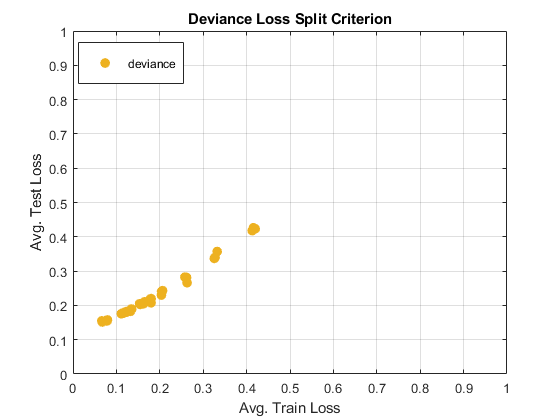

treeDevianceSplitResults.plotCriteriaLoss("Deviance Loss Split Criterion");

## Plot Loss comparison

  LetterDecisionTreeResults with properties:

             resultsTable: [36×12 table]
       resultsColumnNames: [1×12 string]
    outputResultsFilename: "treeSelectDevianceSplitResults.csv"
               fileHandle: -1



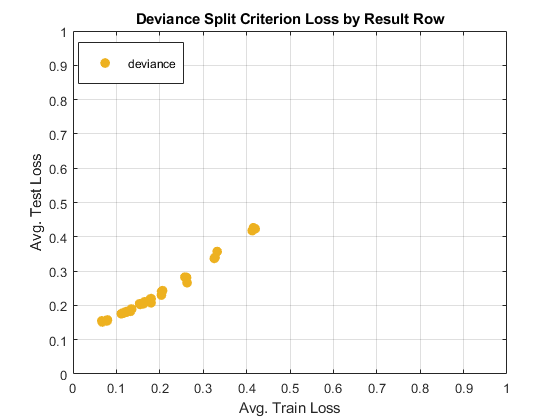

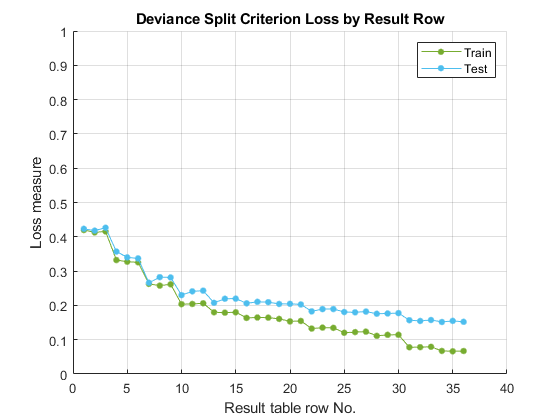

    numberOfHoldOutRun    trainValidateProportion    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    __________________    _______________________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________

             1                      0.8                   50         {'deviance'}        0.4198         0.4233         0.5746           0.574        0.6562      0.6123       3199         1.2656   


displayFeatureResults(treeDevianceSplitResults, "Deviance Split Criterion Loss by Result Row");

%treeDevianceSplitResults.plotLossTestTrainComparison("Deviance Split Criterion Loss by Result Row")

## Perform final test using optimal hyperparameters on complete dataset

load letterDatasetClass.mat;
finalHyperparameters = DTreeHyperparametersClass.getFinalHyperparameterInstance();
treeFinalFeatureClass = LetterDecisionTreeClass(letterDatasetStandardised);
% display info during run?
treeFinalFeatureClass.debug = false;
treeFinalFeatureResults = treeFinalFeatureClass.performFinalDTreeHyperparameterAnalysis(finalHyperparameters, "treeFinalFeatureResults.csv");

Starting final decision tree analysis...
Completed final decision tree analysis


  LetterDecisionTreeResults with properties:

             resultsTable: [18×12 table]
       resultsColumnNames: [1×12 string]
    outputResultsFilename: "treeFinalFeatureResults.csv"
               fileHandle: -1



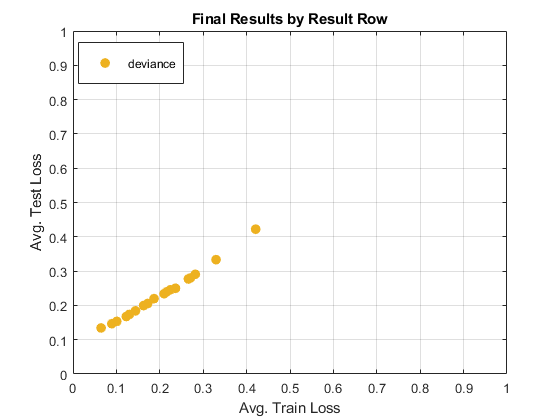

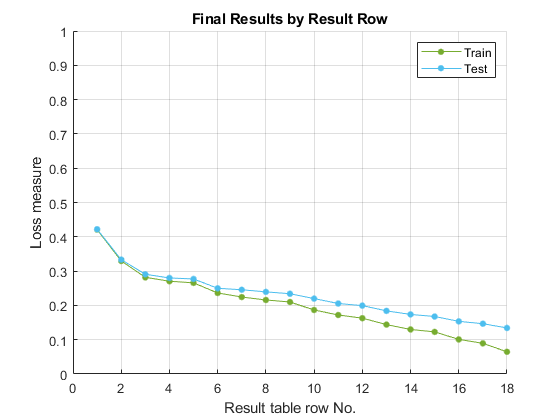

    numberOfHoldOutRun    trainValidateProportion    maxNumSplit    splitCriterion    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    __________________    _______________________    ___________    ______________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________

            1                       0.8                   50         {'deviance'}         0.421         0.4222         0.5763           0.576        0.6633      0.6166       4000            0.5   


displayFeatureResults(treeFinalFeatureResults, "Final Results by Result Row");

## Functions defined for the initial tests

function results = performQuickTreeAnalysis(letterDataset, resultsCsvFilename)
  treeClass = LetterDecisionTreeClass(letterDataset);
  % get an initial set of hyperparameters to try, the results allow a finer
  % selection to be made later
  treeClass.debug = false;
  allFeaturesHyperparameters = DTreeHyperparametersClass.getQuickTestRunInstance();
  results = treeClass.performDTreeHyperameterAnalysis(allFeaturesHyperparameters, resultsCsvFilename);
end

Perform decision hyperparameter analysis on all features

function results = performTreeAnalysis(letterDataset, resultsCsvFilename)
  treeClass = LetterDecisionTreeClass(letterDataset);
  % get an initial set of hyperparameters to try, the results allow a finer
  % selection to be made later
  treeClass.debug = false;
  allFeaturesHyperparameters = DTreeHyperparametersClass.getInstance();
  results = treeClass.performDTreeHyperameterAnalysis(allFeaturesHyperparameters, resultsCsvFilename);
end

## Display Plot results: deviance split criterion looks more accurate

test / train Loss plot (the plot is used to select the most accurate split criterion

function displayFeatureResults(featureResults, plotTitle)
  disp(featureResults);
  featureResults.plotCriteriaLoss(plotTitle)
  PlotUtil.plotLossTestTrainComparison(featureResults.resultsTable,plotTitle);
  disp(featureResults.resultsTable);
end

## display tree

%treeModel = decisionTree.buildSimpleTree()
%decisionTree.displayTree(treeModel)

## Cross validation loss: 37.44%, or approx 62% accurrate, the paper mentions 80% Loss.

%{
cvTree = crossval(treeModel, 'KFold', 5)
% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(cvTree);

% Compute validation Loss
[x, y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
validationLoss = 1 - kfoldLoss(cvTree, 'LossFun', 'ClassifError');
yTrain = categorical(table2cell(y));
% Plot confusion matrix
matrix = confusionmat(yTrain, validationPredictions);
confusionchart(matrix)

%}